# Population analysis of Time varying rate during Operant

The objective here is to identify cells that have some information about vocal production. I contrast the population time varying activity of Listener bats with that of vocalizer bats to identify such cells.

This code is version of population_PCA_GLM.mlx where I tried to see if focusing on Trills only would help better find cells than when pooling all Trills and non-Trills data together.

The conclusion is that PCA GLM might not be the best approach to find which of the vocalizer cells have a different profile than listener cells. In the end, the profile of listener might be too close of that of vocalizer but for different reasons (probably the increase in rate just after the onset of vocalizations is a major reward signal, because the Trill is a super Trigger.

Even trying lowering the thershold on the detection of "significant" cells of vocalizer in the PCA space with respect to the distribution of listener cells in that same space is not making things better. There are some cells that obviusly are driven by the production of the vocalization that don't get detected. So maybe best approach stays to get back to the coherence analysis on Trills only and get the 25 percentile cells that have the highest values of info?

% Path 2 Data
Path2AllData = '/Volumes/JulieE8T/LMCResults';
% Path2AllData = '/Users/elie/Documents/LMCResults';
addpath(genpath('/Users/elie/Documents/CODE/GitHub/GeneralCode'))
addpath(genpath('/Users/elie/Documents/CODE/GitHub/LMC'))
% Let's find the date of interest in the Google sheet
% Path2RecordingTable = '/Users/elie/Google Drive/BatmanData/RecordingLogs/recording_logs.xlsx';
% [~,~,RecTableData]=xlsread(Path2RecordingTable,1,'A1:AF200','basic');
% Header = RecTableData(1,:);
% ND_IDCol = find(contains(Header, 'Neural data voc in operant + PSTH'));
% BatIDCol = find(contains(Header, 'Bat'));
% NLCol = find(contains(Header, 'NL'));
% Dates_Ind = find(cell2mat(RecTableData(2:end,ND_IDCol))==1)+1;
% Dates = cell2mat(RecTableData(Dates_Ind,1));
ThreshSig=50;


## Loop through spike sorting units and evaluate quality (This step has been last run on 06/29/2022)

% Load the list of Spike sorted units generated by
% wrapper_allbehav_neuroscript
load( 'GoodCellIndicesAll.mat', 'ListSSU')
NU = length(ListSSU);

SSQ = cell(NU,1);
SNR = nan(NU,1);
ContamInd = nan(NU,1);
ISIViolation = nan(NU,1);
SubjID = cell(NU,1);
ListCells = cell(NU,1);
for ss=1:NU
    fprintf(1,'File %d/%d\n',ss,NU)
    [~,FileName] = fileparts(ListSSU{ss});
    Ind_ = strfind(FileName,'_');
    SubjectID_local = FileName(1:5);
    Date = FileName(7:14);
    TetrodeID = FileName(Ind_(2)+3);
    SSQ_local = FileName(Ind_(3)+3);
    SSID = FileName(Ind_(4)+1:end);
    ListCells{ss} = fullfile(Path2AllData,sprintf('%s_%s_SS%s_%s-%s.mat', SubjectID_local, Date,SSQ_local,TetrodeID,SSID));
    Data=load(ListCells{ss});
    SubjID{ss} = SubjectID_local;
    SNR(ss) = max(Data.QualitySSU.SNR);
    ContamInd(ss) = Data.QualitySSU.ContamInd;
    ISIViolation(ss) = Data.QualitySSU.ISIViolation;
    if (SNR(ss)>=5) && (ISIViolation(ss)<=1) && (ContamInd(ss)<=0.2)
        SSQ{ss} = 'SSSU';
    elseif (SNR(ss)>=2)
        SSQ{ss} = 'SSMU';
    else
        SSQ{ss} = 'NOISE';
    end
end

File 1/1177
File 2/1177
File 3/1177
File 4/1177
File 5/1177
File 6/1177
File 7/1177
File 8/1177
File 9/1177
File 10/1177
File 11/1177
File 12/1177
File 13/1177
File 14/1177
File 15/1177
File 16/1177
File 17/1177
File 18/1177
File 19/1177
File 20/1177
File 21/1177
File 22/1177
File 23/1177
File 24/1177
File 25/1177
File 26/1177
File 27/1177
File 28/1177
File 29/1177
File 30/1177
File 31/1177
File 32/1177
File 33/1177
File 34/1177
File 35/1177
File 36/1177
File 37/1177
File 38/1177
File 39/1177
File 40/1177
File 41/1177
File 42/1177
File 43/1177
File 44/1177
File 45/1177
File 46/1177
File 47/1177
File 48/1177
File 49/1177
File 50/1177
File 51/1177
File 52/1177
File 53/1177
File 54/1177
File 55/1177
File 56/1177
File 57/1177
File 58/1177
File 59/1177
File 60/1177
File 61/1177
File 62/1177
File 63/1177
File 64/1177
File 65/1177
File 66/1177
File 67/1177
File 68/1177
File 69/1177
File 70/1177
File 71/1177
File 72/1177
File 73/1177
File 74/1177
File 75/1177
File 76/1177
File 77/1177
File 78/

SSSU = (SNR>=5) .* (ISIViolation<=1) .* (ContamInd<=0.2);
SSMU = ~SSSU .* (SNR>=2);
NOISE = SNR<2;
C = [NOISE SSSU SSMU];
fprintf('Number of single units: %d/%d, %.2f%%\n',sum(SSSU), NU,sum(SSSU)/NU*100)

Number of single units: 440/1177, 37.38%


fprintf('Number of multi-units: %d/%d, %.2f%%\n',sum(SSMU), NU,sum(SSMU)/NU*100)

Number of multi-units: 734/1177, 62.36%


fprintf('Number of Noise units: %d/%d, %.2f%%\n',sum(NOISE), NU,sum(NOISE)/NU*100)

Number of Noise units: 3/1177, 0.25%


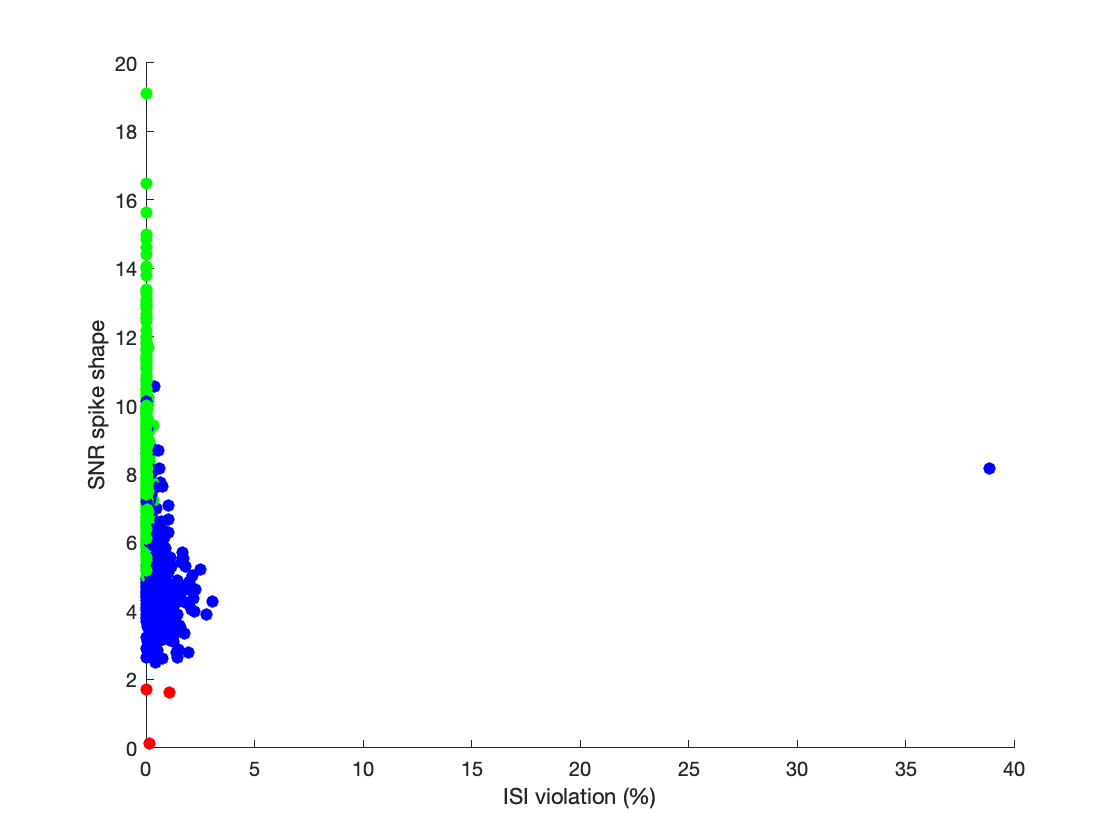


% GoodCellIndices = find(contains(SSQ, 'SS'));

% C = [contains(SSQ, 'NOISE') contains(SSQ, 'SSSU') contains(SSQ, 'SSMU')];
scatter(ISIViolation, SNR,40,C,'filled')
xlabel('ISI violation (%)')
ylabel('SNR spike shape')

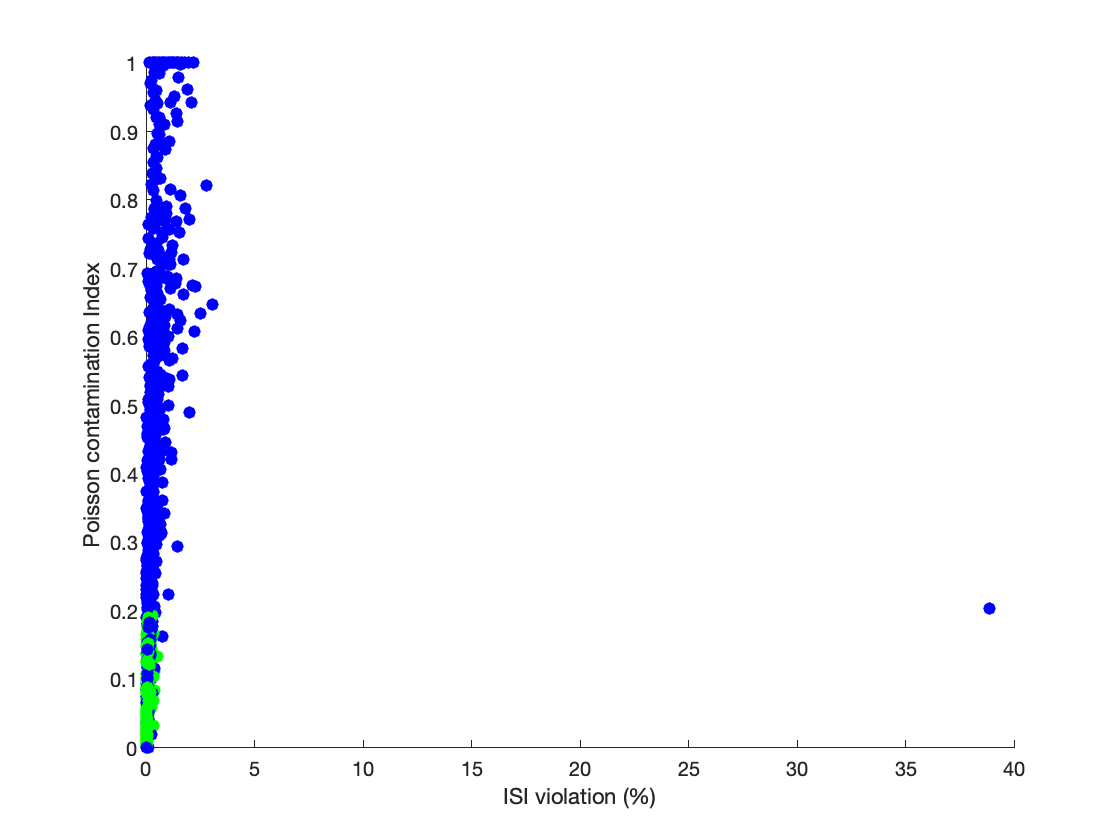

ContamInd(ContamInd>1)=1; %saturate the ContamInd, everything above 1 is just highly contaminated
scatter(ISIViolation,ContamInd, 40, C,'filled')
xlabel('ISI violation (%)')
ylabel('Poisson contamination Index')

## Gather KDE onset of all cells for Ba and Tr in Operant and Free sessions (Last run on 07/01/2022)

% gather the data
% There are weird effect of convolution at edges so Trim data 500ms
Trim = 500;
Tstart = -5000;
GoodCellIndices = sort([find(SSSU); find(SSMU)]);
GC = length(GoodCellIndices);
KDE_onset = cell(GC,9); % first column SelfBaOp, 2nd, SelfTrOp; 3rd SelfVocOp; 4th column SelfBaFr, 5th, SelfTrFr; 6th SelfVocFr; 7th column OthersBaOp, 8th, OthersTrOp; 9th OthersVocOp;
T_onset = cell(GC,2);
Tmax = nan(GC,9);
MeanKDEBaTrOp = nan(GC,1);
StdKDEBaTrOp = nan(GC,1);
MeanKDEBaTrFr = nan(GC,1);
StdKDEBaTrFr = nan(GC,1);
MeanKDEBaTrOpFr = nan(GC,1);
StdKDEBaTrOpFr = nan(GC,1);
MeanKDEAllVocOp = nan(GC,1);
StdKDEAllVocOp = nan(GC,1);
MeanKDEAllVocFr = nan(GC,1);
StdKDEAllVocFr = nan(GC,1);
MeanKDEAllVocOpFr = nan(GC,1);
StdKDEAllVocOpFr = nan(GC,1);
OperantVocalizer = nan(GC,1);
for ss=1:GC
    fprintf(1,'File %d/%d\n',ss,GC)
    Data=load(ListCells{GoodCellIndices(ss)});
    if isfield(Data,'KDE_onset') && isfield(Data.KDE_onset, 'SelfBaOp')
        if contains(ListCells{GoodCellIndices(ss)}, '65701')
            warning('Unexpected that 65701 has vocalproduction in Operant')
            keyboard
        end
        OperantVocalizer(ss) = 1;
        Tmax(ss,1) = max(Data.KDE_onset.SelfBaOp(2,(1:(end-Trim))));
        KDE_onset{ss,1} = Data.KDE_onset.SelfBaOp(1,find(Data.KDE_onset.SelfBaOp(2,:)==(Tstart+Trim)):(end-Trim));
    end
    if isfield(Data,'KDE_onset') && isfield(Data.KDE_onset, 'SelfTrOp')
        if contains(ListCells{GoodCellIndices(ss)}, '65701')
            warning('Unexpected that 65701 has vocalproduction in Operant')
            keyboard
        end
        OperantVocalizer(ss) = 1;
        Tmax(ss,2) = max(Data.KDE_onset.SelfTrOp(2,1:(end-Trim)));
        KDE_onset{ss,2} = Data.KDE_onset.SelfTrOp(1,find(Data.KDE_onset.SelfTrOp(2,:)==(Tstart+Trim)):(end-Trim));
    end
    if isfield(Data,'KDE_onset') && isfield(Data.KDE_onset, 'SelfVocOp')
        if contains(ListCells{GoodCellIndices(ss)}, '65701')
            warning('Unexpected that 65701 has vocalproduction in Operant')
            keyboard
        end
        OperantVocalizer(ss) = 1;
        Tmax(ss,3) = max(Data.KDE_onset.SelfVocOp(2,1:(end-Trim)));
        KDE_onset{ss,3} = Data.KDE_onset.SelfVocOp(1,find(Data.KDE_onset.SelfVocOp(2,:)==(Tstart+Trim)):(end-Trim));
        MeanKDEAllVocOp(ss) = nanmean(KDE_onset{ss,3}); 
        StdKDEAllVocOp(ss) = nanstd(KDE_onset{ss,3}); 
    end
    
    if isfield(Data,'KDE_onset') && isfield(Data.KDE_onset, 'SelfBaFr')
        Tmax(ss,4) = max(Data.KDE_onset.SelfBaFr(2,1:(end-Trim)));
        KDE_onset{ss,4} = Data.KDE_onset.SelfBaFr(1,find(Data.KDE_onset.SelfBaFr(2,:)==(Tstart+Trim)):(end-Trim));
    end
    if isfield(Data,'KDE_onset') && isfield(Data.KDE_onset, 'SelfTrFr')
        Tmax(ss,5) = max(Data.KDE_onset.SelfTrFr(2,1:(end-Trim)));
        KDE_onset{ss,5} = Data.KDE_onset.SelfTrFr(1,find(Data.KDE_onset.SelfTrFr(2,:)==(Tstart+Trim)):(end-Trim));
    end
    if isfield(Data,'KDE_onset') && isfield(Data.KDE_onset, 'SelfVocFr')
        Tmax(ss,6) = max(Data.KDE_onset.SelfVocFr(2,1:(end-Trim)));
        KDE_onset{ss,6} = Data.KDE_onset.SelfVocFr(1,find(Data.KDE_onset.SelfVocFr(2,:)==(Tstart+Trim)):(end-Trim));
        MeanKDEAllVocFr(ss) = nanmean(KDE_onset{ss,6}); 
        StdKDEAllVocFr(ss) = nanstd(KDE_onset{ss,6}); 
    end
    MeanKDEBaTrFr(ss) = nanmean([KDE_onset{ss,4} KDE_onset{ss,5}]); 
    StdKDEBaTrFr(ss) = nanstd([KDE_onset{ss,4} KDE_onset{ss,5}]); 
    MeanKDEBaTrOpFr(ss) = nanmean([KDE_onset{ss,4} KDE_onset{ss,5} KDE_onset{ss,1} KDE_onset{ss,2}]); 
    StdKDEBaTrOpFr(ss) = nanstd([KDE_onset{ss,4} KDE_onset{ss,5} KDE_onset{ss,1} KDE_onset{ss,2}]);
    MeanKDEAllVocOpFr(ss) = nanmean([KDE_onset{ss,3} KDE_onset{ss,6}]); 
    StdKDEAllVocOpFr(ss) = nanstd([KDE_onset{ss,3} KDE_onset{ss,6}]); 

    if isfield(Data,'KDE_onset') && isfield(Data.KDE_onset, 'OthersBaOp')
        if contains(ListCells{GoodCellIndices(ss)}, '59834') || contains(ListCells{GoodCellIndices(ss)}, '11689')
            warning('Unexpected that 59834 or 11689 has vocal perception in Operant')
            keyboard
        end
        OperantVocalizer(ss) = 0;
        Tmax(ss,7) = max(Data.KDE_onset.OthersBaOp(2,(1:(end-Trim))));
        KDE_onset{ss,7} = Data.KDE_onset.OthersBaOp(1,find(Data.KDE_onset.OthersBaOp(2,:)==(Tstart+Trim)):(end-Trim));
    end
    if isfield(Data,'KDE_onset') && isfield(Data.KDE_onset, 'OthersTrOp')
        if contains(ListCells{GoodCellIndices(ss)}, '59834') || contains(ListCells{GoodCellIndices(ss)}, '11689')
            warning('Unexpected that 59834 or 11689 has vocal perception in Operant')
            keyboard
        end
        OperantVocalizer(ss) = 0;
        Tmax(ss,8) = max(Data.KDE_onset.OthersTrOp(2,1:(end-Trim)));
        KDE_onset{ss,8} = Data.KDE_onset.OthersTrOp(1,find(Data.KDE_onset.OthersTrOp(2,:)==(Tstart+Trim)):(end-Trim));
    end
    if isfield(Data,'KDE_onset') && isfield(Data.KDE_onset, 'OthersVocOp')
        if contains(ListCells{GoodCellIndices(ss)}, '59834') || contains(ListCells{GoodCellIndices(ss)}, '11689')
            warning('Unexpected that 59834 or 11689 has vocal perception in Operant')
            keyboard
        end
        OperantVocalizer(ss) = 0;
        Tmax(ss,9) = max(Data.KDE_onset.OthersVocOp(2,1:(end-Trim)));
        KDE_onset{ss,9} = Data.KDE_onset.OthersVocOp(1,find(Data.KDE_onset.OthersVocOp(2,:)==(Tstart+Trim)):(end-Trim));
        MeanKDEAllVocOp(ss) = nanmean(KDE_onset{ss,9}); 
        StdKDEAllVocOp(ss) = nanstd(KDE_onset{ss,9}); 
    end
    if OperantVocalizer(ss)
        MeanKDEBaTrOp(ss) = nanmean([KDE_onset{ss,1} KDE_onset{ss,2}]); 
        StdKDEBaTrOp(ss) = nanstd([KDE_onset{ss,1} KDE_onset{ss,2}]); 
    else
        MeanKDEBaTrOp(ss) = nanmean([KDE_onset{ss,7} KDE_onset{ss,8}]); 
        StdKDEBaTrOp(ss) = nanstd([KDE_onset{ss,7} KDE_onset{ss,8}]); 
    end

end

File 1/1174
File 2/1174
File 3/1174
File 4/1174
File 5/1174
File 6/1174
File 7/1174
File 8/1174
File 9/1174
File 10/1174
File 11/1174
File 12/1174
File 13/1174
File 14/1174
File 15/1174
File 16/1174
File 17/1174
File 18/1174
File 19/1174
File 20/1174
File 21/1174
File 22/1174
File 23/1174
File 24/1174
File 25/1174
File 26/1174
File 27/1174
File 28/1174
File 29/1174
File 30/1174
File 31/1174
File 32/1174
File 33/1174
File 34/1174
File 35/1174
File 36/1174
File 37/1174
File 38/1174
File 39/1174
File 40/1174
File 41/1174
File 42/1174
File 43/1174
File 44/1174
File 45/1174
File 46/1174
File 47/1174
File 48/1174
File 49/1174
File 50/1174
File 51/1174
File 52/1174
File 53/1174
File 54/1174
File 55/1174
File 56/1174
File 57/1174
File 58/1174
File 59/1174
File 60/1174
File 61/1174
File 62/1174
File 63/1174
File 64/1174
File 65/1174
File 66/1174
File 67/1174
File 68/1174
File 69/1174
File 70/1174
File 71/1174
File 72/1174
File 73/1174
File 74/1174
File 75/1174
File 76/1174
File 77/1174
File 78/

save(fullfile(Path2AllData,'population_PCA_GLM_data.mat'), 'SSQ','SNR','ContamInd', 'ISIViolation', 'SubjID','SSSU', 'SSMU', 'ListCells','GoodCellIndices', 'KDE_onset','T_onset', 'Tmax', 'MeanKDEBaTrOp', 'StdKDEBaTrOp','StdKDEBaTrFr','MeanKDEBaTrFr','MeanKDEBaTrOpFr', 'StdKDEBaTrOpFr','MeanKDEAllVocOp','StdKDEAllVocOp','MeanKDEAllVocFr','StdKDEAllVocFr', 'MeanKDEAllVocOpFr','StdKDEAllVocOpFr','OperantVocalizer')

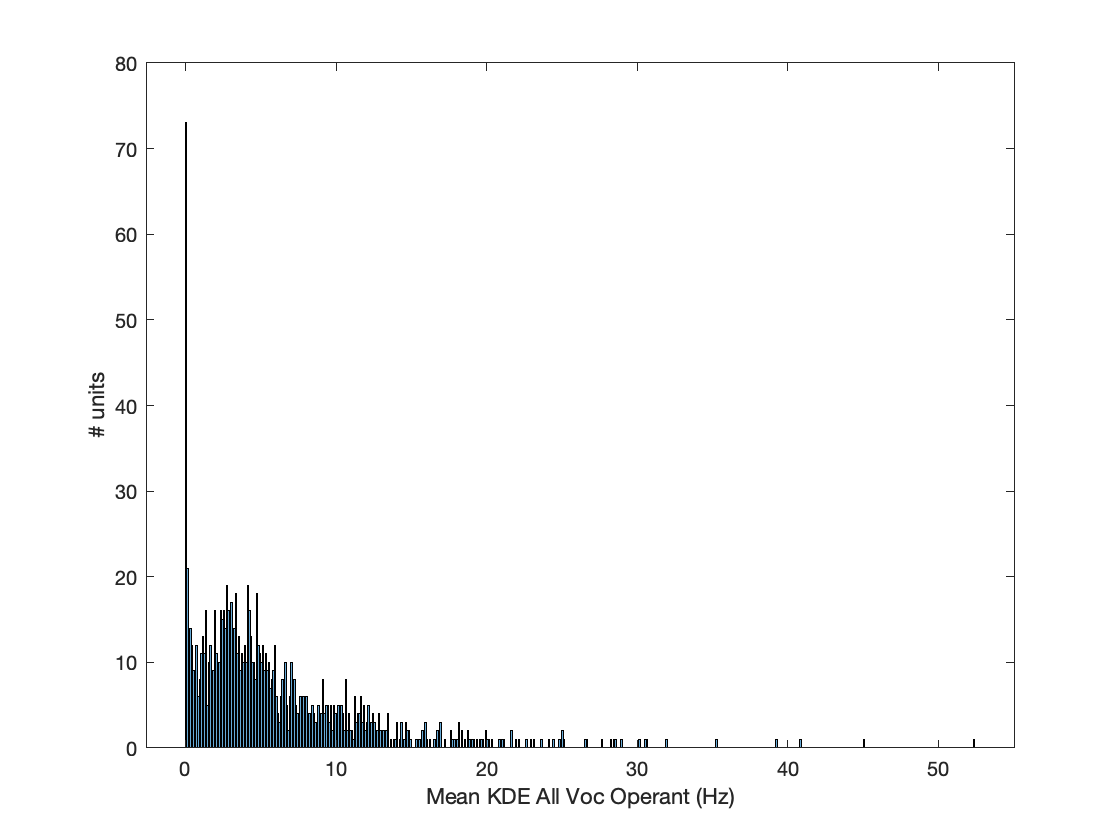

% Explore the average spike rates and get rid of non active cells?
histogram(MeanKDEAllVocOp,'BinWidth',0.1)
xlabel('Mean KDE All Voc Operant (Hz)')
ylabel('# units')
hold off

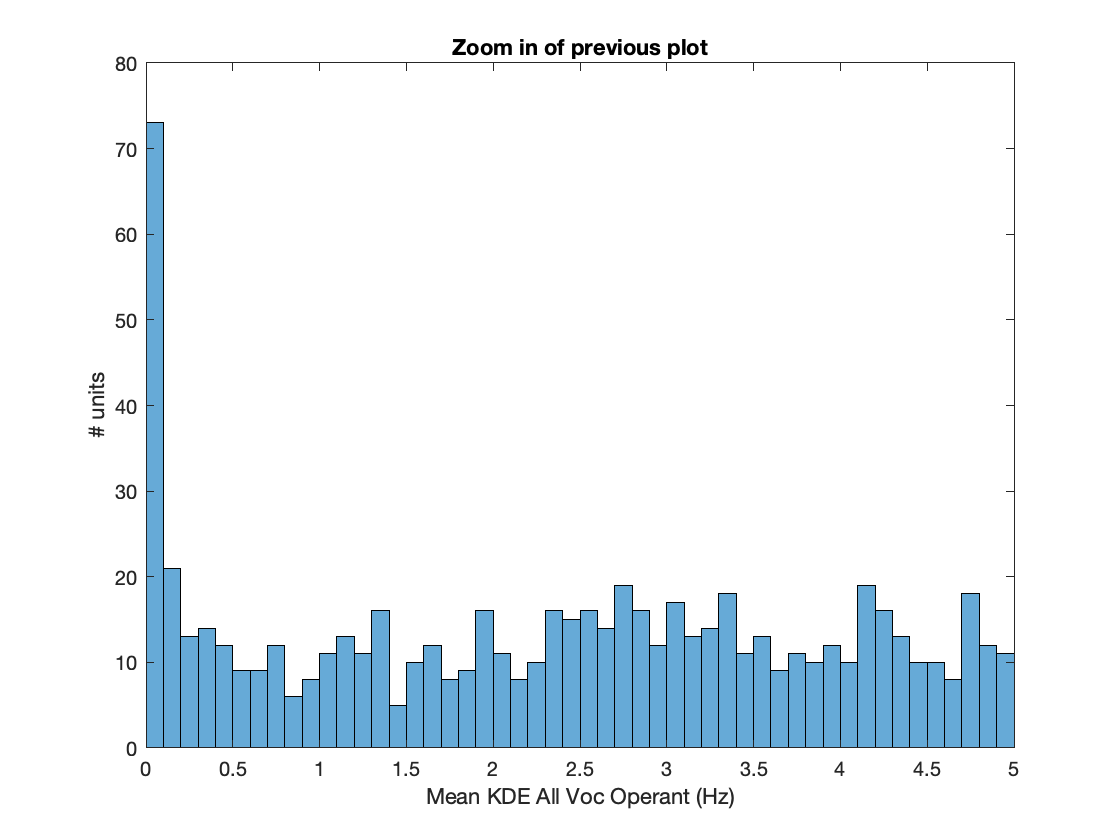

histogram(MeanKDEAllVocOp,'BinWidth',0.1)
xlabel('Mean KDE All Voc Operant (Hz)')
ylabel('# units')
title('Zoom in of previous plot')
xlim([0 5])
hold off

ActiveCells01 = find(MeanKDEAllVocOp>0.1);
fprintf(1,'Number of active cells in operant session: %d/%d',length(ActiveCells01), length(MeanKDEAllVocOp))

Number of active cells in operant session: 1101/1174

### Let's try a PCA on the ZS but feeding independently BA and Tr

% Data loader to skip previous cells
load(fullfile(Path2AllData,'population_PCA_GLM_data.mat'), 'ListCells', 'GoodCellIndices','MeanKDEAllVocOp', 'Tmax','MeanKDEBaTrOp','StdKDEBaTrOp')

% Variables reinitialisation to skip previous steps
Trim = 500;
Tstart = -5000;

% Trim the data of active cells in time and create a matrix of all the
% z-scored KDE Tr and Ba Op For both Hearing and vocalizing bats (last run
% on 07/01/2022)

% Cells that are either SMU or SSU
ListCellsG = ListCells(GoodCellIndices);
% Active Cells
ActiveCells01 = MeanKDEAllVocOp>0.1;
ListCellsGA = ListCellsG(ActiveCells01);
% select cells that are either from vocalizer or listener of either Trills and non-trills during operant and that have a minimum average rate over all voc of 0.1Hz
BaorTr_0ind = logical((~isnan(Tmax(:,1)) + ~isnan(Tmax(:,7)) + ~isnan(Tmax(:,2)) + ~isnan(Tmax(:,8))).* (~isnan(MeanKDEBaTrOp)).*(MeanKDEAllVocOp>0.1)); 
BaorTr_Ind = find(BaorTr_0ind);
% select cells that are from vocalizer or Listener of either Trills and non-trills during operant and that have a minimum average rate over all voc of 0.1Hz
ListCellsGAOp = ListCellsG(BaorTr_0ind);

fprintf(1, 'Active cells defined as having a minimum time and vocalization average rate of 0.1Hz: %d/%d', sum(ActiveCells01), length(MeanKDEAllVocOp))

Active cells defined as having a minimum time and vocalization average rate of 0.1Hz: 1101/1174

fprintf('The PCA on time varying rate during Operant can be performed on the data of %d/%d\n',sum(BaorTr_0ind),length(ActiveCells01))

The PCA on time varying rate during Operant can be performed on the data of 1101/1174



% find the minimum duration of the KDE for all cells
TAll = length(Tstart+Trim:min([Tmax(:,1); Tmax(:,2); Tmax(:,7); Tmax(:,8)]))

TAll = 9084

KDE_onset_Mat_nTr = nan(sum(BaorTr_0ind),TAll);
KDE_onset_Mat_Tr = nan(sum(BaorTr_0ind),TAll);
for ss=1:sum(BaorTr_0ind)
    fprintf(1,'File %d/%d: %s\n',ss,sum(BaorTr_0ind), ListCellsGAOp{ss})
    if OperantVocalizer(BaorTr_Ind(ss))
        if ~isempty(KDE_onset{BaorTr_Ind(ss),1})
            KDE_onset_Mat_nTr(ss,:) = (KDE_onset{BaorTr_Ind(ss),1}(1:TAll) -MeanKDEBaTrOp(BaorTr_Ind(ss)))./StdKDEBaTrOp(BaorTr_Ind(ss));
        end 
        if ~isempty(KDE_onset{BaorTr_Ind(ss),2})
            KDE_onset_Mat_Tr(ss,:) = (KDE_onset{BaorTr_Ind(ss),2}(1:TAll) -MeanKDEBaTrOp(BaorTr_Ind(ss)))./StdKDEBaTrOp(BaorTr_Ind(ss));
        end
    else
        if ~isempty(KDE_onset{BaorTr_Ind(ss),7})
            KDE_onset_Mat_nTr(ss,:) = (KDE_onset{BaorTr_Ind(ss),7}(1:TAll) -MeanKDEBaTrOp(BaorTr_Ind(ss)))./StdKDEBaTrOp(BaorTr_Ind(ss));
        end
        if ~isempty(KDE_onset{BaorTr_Ind(ss),8})
            KDE_onset_Mat_Tr(ss,:) = (KDE_onset{BaorTr_Ind(ss),8}(1:TAll) -MeanKDEBaTrOp(BaorTr_Ind(ss)))./StdKDEBaTrOp(BaorTr_Ind(ss));
        end
    end
end

File 1/1101: /Volumes/JulieE8T/LMCResults/59834_20190604_SSS_3-109.mat
File 2/1101: /Volumes/JulieE8T/LMCResults/59834_20190604_SSS_3-111.mat
File 3/1101: /Volumes/JulieE8T/LMCResults/59834_20190604_SSS_3-191.mat
File 4/1101: /Volumes/JulieE8T/LMCResults/59834_20190604_SSS_4-193.mat
File 5/1101: /Volumes/JulieE8T/LMCResults/59834_20190604_SSS_4-197.mat
File 6/1101: /Volumes/JulieE8T/LMCResults/59834_20190604_SSM_1-201.mat
File 7/1101: /Volumes/JulieE8T/LMCResults/59834_20190604_SSM_1-206.mat
File 8/1101: /Volumes/JulieE8T/LMCResults/59834_20190604_SSM_1-233.mat
File 9/1101: /Volumes/JulieE8T/LMCResults/59834_20190604_SSM_2-208.mat
File 10/1101: /Volumes/JulieE8T/LMCResults/59834_20190604_SSM_3-115.mat
File 11/1101: /Volumes/JulieE8T/LMCResults/59834_20190604_SSM_3-213.mat
File 12/1101: /Volumes/JulieE8T/LMCResults/59834_20190604_SSM_3-229.mat
File 13/1101: /Volumes/JulieE8T/LMCResults/59834_20190604_SSM_4-135.mat
File 14/1101: /Volumes/JulieE8T/LMCResults/59834_20190604_SSM_4-241.mat
F

save(fullfile(Path2AllData,'population_PCA_GLM_data.mat'), 'KDE_onset_Mat_nTr','KDE_onset_Mat_Tr', 'BaorTr_Ind','BaorTr_0ind','ListCellsGAOp', '-append')

% run PCA on the ZS of the operant KDE Trills ONLY (This is where this
% notebook diverge from the original population_PCA_GLM.mlx)
NanTr = isnan(KDE_onset_Mat_Tr(:,1));
fprintf(1,'%d cells are represented in this Trill dataset\n', sum(~NanTr));

1047 cells are represented in this Trill dataset


[PC,Score,~, ~, VarExpl,~] = pca(KDE_onset_Mat_Tr(~NanTr,:));

ListCellsGAOpScore = ListCellsGAOp(~NanTr); % List of cells in Score

% Plot the cumulative explained variance as a function of # PCs
plot(cumsum(VarExpl), 'LineWidth',2);xlabel('#PC');ylabel('Proportion variance explained by PCA)'); xlim([0 30])
title('PCA on KDE of Trill')

% Plot the first PC shapes
plot(PC(:,1), 'LineWidth',2);hold on;plot(PC(:,2), 'LineWidth',2);plot(PC(:,3), 'LineWidth',2);plot(PC(:,4), 'LineWidth',2);plot(PC(:,5), 'LineWidth',2);plot(PC(:,6), 'LineWidth',2);plot(PC(:,7), 'LineWidth',2);plot(PC(:,8), 'LineWidth',2);plot(PC(:,9), 'LineWidth',2);plot(PC(:,10), 'LineWidth',2);legend('PC1', 'PC2','PC3', 'PC4', 'PC5', 'PC6','PC7','PC8','PC9','PC10', 'Location', 'EastOutside'); ylabel('PCA coefficients');xlabel('Time (s)');xticks([1 -(Tstart+Trim)]);xticklabels([(Tstart+Trim)/10^3 0]);title('PCA on KDE of Trill')
hold off

% Plot swarmplots of PC weights (scores) with color coded if a cell is from a
% vocalizer or listener
NanTr = isnan(KDE_onset_Mat_Tr(:,1));
OperantVocalizerCells01 = OperantVocalizer(BaorTr_0ind);
OVT_cells = logical(OperantVocalizerCells01(~NanTr)); % Vocalizer cells=1
fprintf(1,'There are %d/%d cells from Trills vocalizers\n',sum(OVT_cells), length(OVT_cells))

There are 564/1047 cells from Trills vocalizers


OLT_cells = ~OperantVocalizerCells01(~NanTr);
fprintf(1,'There are %d/%d cells from Trills listeners\n',sum(OLT_cells), length(OLT_cells))

There are 483/1047 cells from Trills listeners


ColPC = get(groot, 'DefaultAxesColorOrder');
ScatterMarkerSz=30;
MeanMarkerSize=14;
PLim = 0.05;
NPC=15;
LMpValVL_Trill = nan(NPC,1);
LMCoeffVL_Trill = nan(NPC,1);
LMRadjVL_Trill = nan(NPC,1);
F3 = figure(3);
clf(F3)
set(F3,'Visible','on')
tiledlayout(2,1)
nexttile
for n=1:NPC
    swarmchart((3*n-1)*ones(sum(OVT_cells),1),Score(OVT_cells,n),ScatterMarkerSz,ColPC(2,:),'o','filled','MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5)
    hold on
    swarmchart((3*n)*ones(sum(OLT_cells),1),Score(OLT_cells,n),ScatterMarkerSz,ColPC(1,:),'o','filled','MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5)
    hold on
    if n==1
        legend({'Vocalizer Trills', 'Listener Trills'})
        legend('Location', 'SouthEast','AutoUpdate','off')
    end
    errorbar((3*n-1),mean(Score(OVT_cells,n),'omitnan'),std(Score(OVT_cells,n), 'omitnan')/sum(OVT_cells)^0.5, 'dk','MarkerSize',MeanMarkerSize,'MarkerFaceColor',ColPC(2,:))
    hold on
    errorbar((3*n),mean(Score(OLT_cells,n),'omitnan'),std(Score(OLT_cells,n),'omitnan')/sum(OLT_cells)^0.5, 'dk','MarkerSize',MeanMarkerSize,'MarkerFaceColor',ColPC(1,:))
    hold on
    Tbl =  table(Score(:,n), logical(OVT_cells),ListCellsGAOp(~NanTr), 'VariableNames', {'PCScore', 'VorL','CellID'});
    lmVL = fitlm(Tbl, 'PCScore~VorL');
    TestLMVL = lmVL.anova;
    LMpValVL_Trill(n) = TestLMVL.pValue(1);
    LMCoeffVL_Trill(n) =  lmVL.Coefficients.Estimate(2);
    LMRadjVL_Trill(n) =   lmVL.Rsquared.Adjusted;
    if LMpValVL_Trill(n)<0.05
        plot((3*n-0.5), 100,'r*','MarkerSize',15);
        fprintf(1,'\n\n\n**********PC%d: Effect of Vocalizer vs Listener\n***********', n)
        lmVL
        fprintf(1, 'Effect of VorL:')
        LMpValVL_Trill(n)
    end
end




**********PC3: Effect of Vocalizer vs Listener
***********

lmVL = Linear regression model:
    PCScore ~ 1 + VorL

Estimated Coefficients:
                   Estimate      SE       tStat      pValue 
                   ________    ______    _______    ________

    (Intercept)    -2.5722     1.3933    -1.8461    0.065153
    VorL_1           4.775     1.8983     2.5154     0.01204


Number of observations: 1047, Error degrees of freedom: 1045
Root Mean Squared Error: 30.6
R-squared: 0.00602,  Adjusted R-Squared: 0.00507
F-statistic vs. constant model: 6.33, p-value = 0.012

Effect of VorL:

ans = 0.0120




**********PC6: Effect of Vocalizer vs Listener
***********

lmVL = Linear regression model:
    PCScore ~ 1 + VorL

Estimated Coefficients:
                   Estimate      SE        tStat      pValue 
                   ________    _______    _______    ________

    (Intercept)     1.2589     0.64286     1.9582    0.050469
    VorL_1         -2.3369     0.87589    -2.6681    0.007747


Number of observations: 1047, Error degrees of freedom: 1045
Root Mean Squared Error: 14.1
R-squared: 0.00677,  Adjusted R-Squared: 0.00582
F-statistic vs. constant model: 7.12, p-value = 0.00775

Effect of VorL:

ans = 0.0077




**********PC7: Effect of Vocalizer vs Listener
***********

lmVL = Linear regression model:
    PCScore ~ 1 + VorL

Estimated Coefficients:
                   Estimate      SE       tStat      pValue 
                   ________    _______    ______    ________

    (Intercept)     1.0496     0.58776    1.7857    0.074438
    VorL_1         -1.9484     0.80082    -2.433    0.015141


Number of observations: 1047, Error degrees of freedom: 1045
Root Mean Squared Error: 12.9
R-squared: 0.00563,  Adjusted R-Squared: 0.00468
F-statistic vs. constant model: 5.92, p-value = 0.0151

Effect of VorL:

ans = 0.0151




**********PC8: Effect of Vocalizer vs Listener
***********

lmVL = Linear regression model:
    PCScore ~ 1 + VorL

Estimated Coefficients:
                   Estimate      SE        tStat      pValue  
                   ________    _______    _______    _________

    (Intercept)    -0.98072    0.47271    -2.0747     0.038261
    VorL_1           1.8206    0.64406     2.8267    0.0047924


Number of observations: 1047, Error degrees of freedom: 1045
Root Mean Squared Error: 10.4
R-squared: 0.00759,  Adjusted R-Squared: 0.00664
F-statistic vs. constant model: 7.99, p-value = 0.00479

Effect of VorL:

ans = 0.0048




**********PC12: Effect of Vocalizer vs Listener
***********

lmVL = Linear regression model:
    PCScore ~ 1 + VorL

Estimated Coefficients:
                   Estimate      SE        tStat      pValue 
                   ________    _______    _______    ________

    (Intercept)    0.56344     0.36659      1.537      0.1246
    VorL_1          -1.046     0.49947    -2.0941    0.036487


Number of observations: 1047, Error degrees of freedom: 1045
Root Mean Squared Error: 8.06
R-squared: 0.00418,  Adjusted R-Squared: 0.00323
F-statistic vs. constant model: 4.39, p-value = 0.0365

Effect of VorL:

ans = 0.0365




**********PC13: Effect of Vocalizer vs Listener
***********

lmVL = Linear regression model:
    PCScore ~ 1 + VorL

Estimated Coefficients:
                   Estimate      SE        tStat       pValue  
                   ________    _______    _______    __________

    (Intercept)    -1.1622     0.34857    -3.3341     0.0008859
    VorL_1          2.1574     0.47492     4.5426    6.2023e-06


Number of observations: 1047, Error degrees of freedom: 1045
Root Mean Squared Error: 7.66
R-squared: 0.0194,  Adjusted R-Squared: 0.0184
F-statistic vs. constant model: 20.6, p-value = 6.2e-06

Effect of VorL:

ans = 6.2023e-06

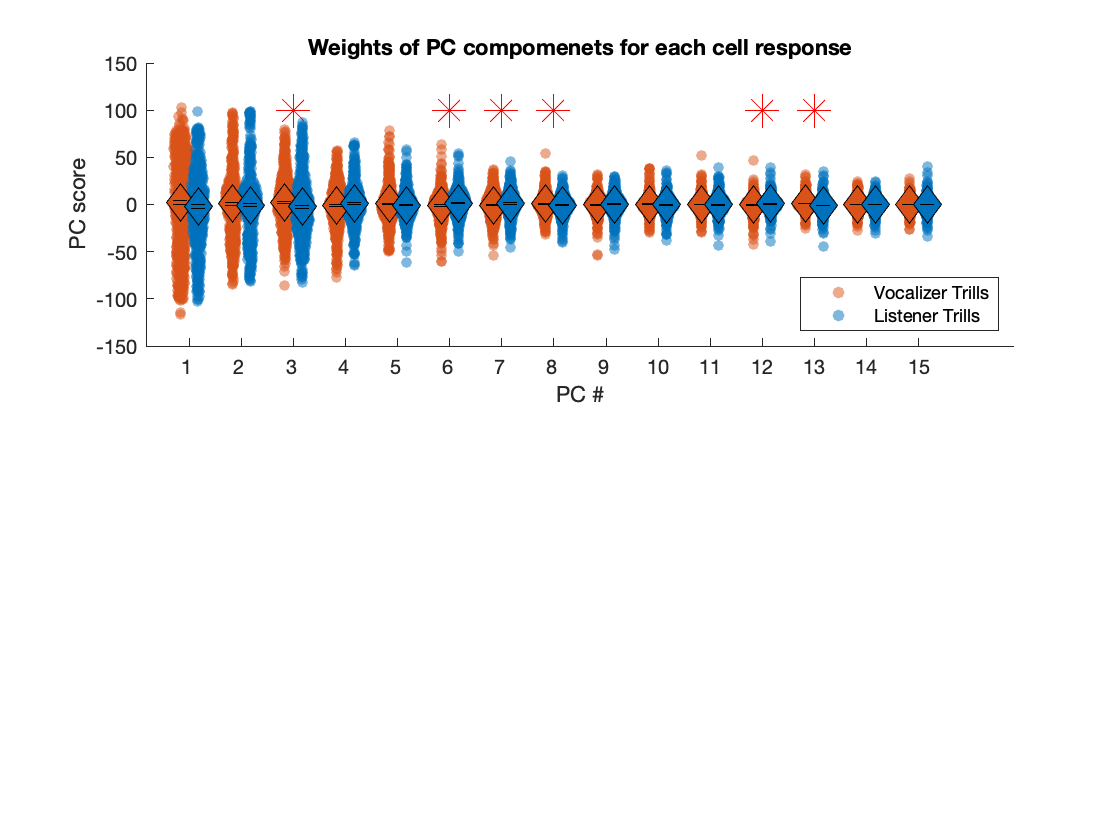

set(gca, 'XTick', 3*(1:NPC)-0.5, 'XTickLabel',1:NPC)
xlabel('PC #')
ylabel('PC score')
title('Weights of PC compomenets for each cell response')
hold off

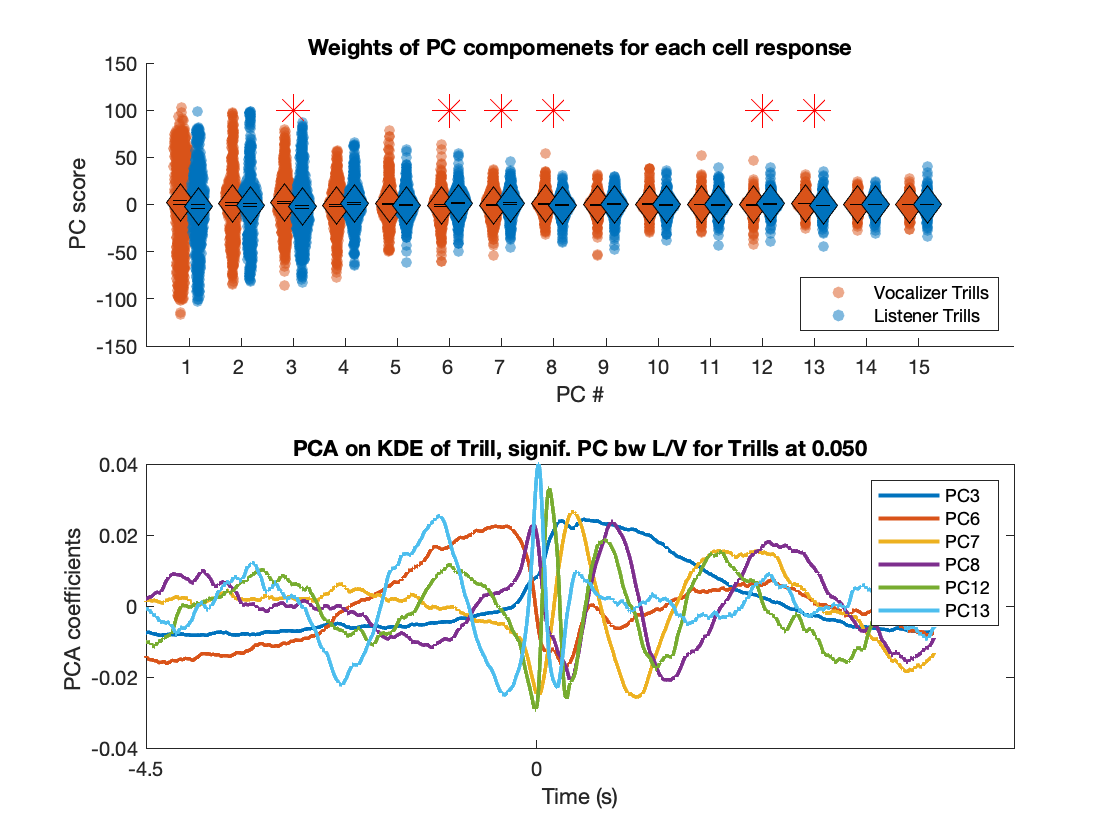

% Plot the PC shapes significant for the effect of Vocalizer/Listner in
% linear models
F3 = figure(3);
nexttile
PCSigT = find(LMpValVL_Trill<PLim);
for n=1:length(PCSigT)
    legend('AutoUpdate',"on")
    plot(PC(:,PCSigT(n)), 'LineWidth',2, 'DisplayName',sprintf('PC%d',PCSigT(n)) );
    hold on;
end
ylabel('PCA coefficients ');
xlabel('Time (s)');
xticks([1 -(Tstart+Trim)]);xticklabels([(Tstart+Trim)/10^3 0]);
title(sprintf('PCA on KDE of Trill, signif. PC bw L/V for Trills at %.3f', PLim))
hold off

% What if we use the distribution of Listener cells as the null
% distribution and select cells that are in the 1percentile of that
% distribution?
% Outstanding cells that are in the 10 percentile of the Listener
% distribution of values
PvalLim = 0.01;
ScoreOVT = Score(OVT_cells,PCSigT);
ScoreOLT = Score(OLT_cells,PCSigT);
% first calculate the probability for each vocalizer response and each PC
% of having a score larger than the expected one from the distribution of
% Listener responses
OutstandingT_pvalue = nan(size(ScoreOVT,1),length(PCSigT));
for rr=1:size(ScoreOVT,1)
    for nPC = 1:length(PCSigT)
        OutstandingT_pvalue(rr,nPC) = 1-(sum(sign(LMCoeffVL_Trill(PCSigT(nPC))).*(ScoreOVT(rr,nPC)-ScoreOLT(:,nPC))>0)/sum(OLT_cells));
    end
end

% Now correct that probability for False discovery rate (True proba =
% p*(Num_comparisons-rank))
% [~,Ord]=sort([OutstandingT_pvalue(:,1);OutstandingT_pvalue(:,2);OutstandingT_pvalue(:,3);OutstandingT_pvalue(:,4); OutstandingT_pvalue(:,5); OutstandingT_pvalue(:,6)]);
% Ord(Ord==length(Ord)) = length(Ord)-1;
% Ord1 = Ord(1:size(ScoreOVT,1));
% Ord2 = Ord(1+size(ScoreOVT,1) : 2*size(ScoreOVT,1));
% Ord3 = Ord(1+2*size(ScoreOVT,1) : 3*size(ScoreOVT,1));
% Ord4 = Ord(1+3*size(ScoreOVT,1) : 4*size(ScoreOVT,1));
% Ord5 = Ord(1+4*size(ScoreOVT,1) : 5*size(ScoreOVT,1));
% Ord6 = Ord(1+5*size(ScoreOVT,1) : 6*size(ScoreOVT,1));
% OutstandingT_pvalueFDR = [OutstandingT_pvalue(:,1).*(6*size(ScoreOVT,1)-Ord1) OutstandingT_pvalue(:,2).*(6*size(ScoreOVT,1)-Ord2) OutstandingT_pvalue(:,3).*(6*size(ScoreOVT,1)-Ord3) OutstandingT_pvalue(:,4).*(6*size(ScoreOVT,1)-Ord4) OutstandingT_pvalue(:,5).*(6*size(ScoreOVT,1)-Ord5) OutstandingT_pvalue(:,6).*(6*size(ScoreOVT,1)-Ord6)];
% OutstandingT = OutstandingT_pvalueFDR<PvalLim;

% Bonferroni correction is another alternative
%  OutstandingT = (OutstandingT_pvalue.*2*size(ScoreOVT,1))<PvalLim;

 % No correction
OutstandingT = (OutstandingT_pvalue)<PvalLim;

% Cells are considered having a profile of a vocalizer if for their response to Trills
% the value of at least one of
% their PC score in the dimension significant in the LM comparing Listener
% and Vocalizer is significantly higher than the distribution of values for
% listener responses with FDR correction
% Now create the long logical vector of Outstanding vocalizer responses in
% the same dimensions as score
OutstandingVoc = nan(size(Score,1),1);
OutstandingVoc(OVT_cells) = logical(sum(OutstandingT,2));

fprintf(1, 'There are %d/%d with a profile of a vocalizer at p=%.2f without FDR correction\n', sum(OutstandingVoc(OVT_cells)), sum(OVT_cells), PLim);

There are 42/564 with a profile of a vocalizer at p=0.05 without FDR correction


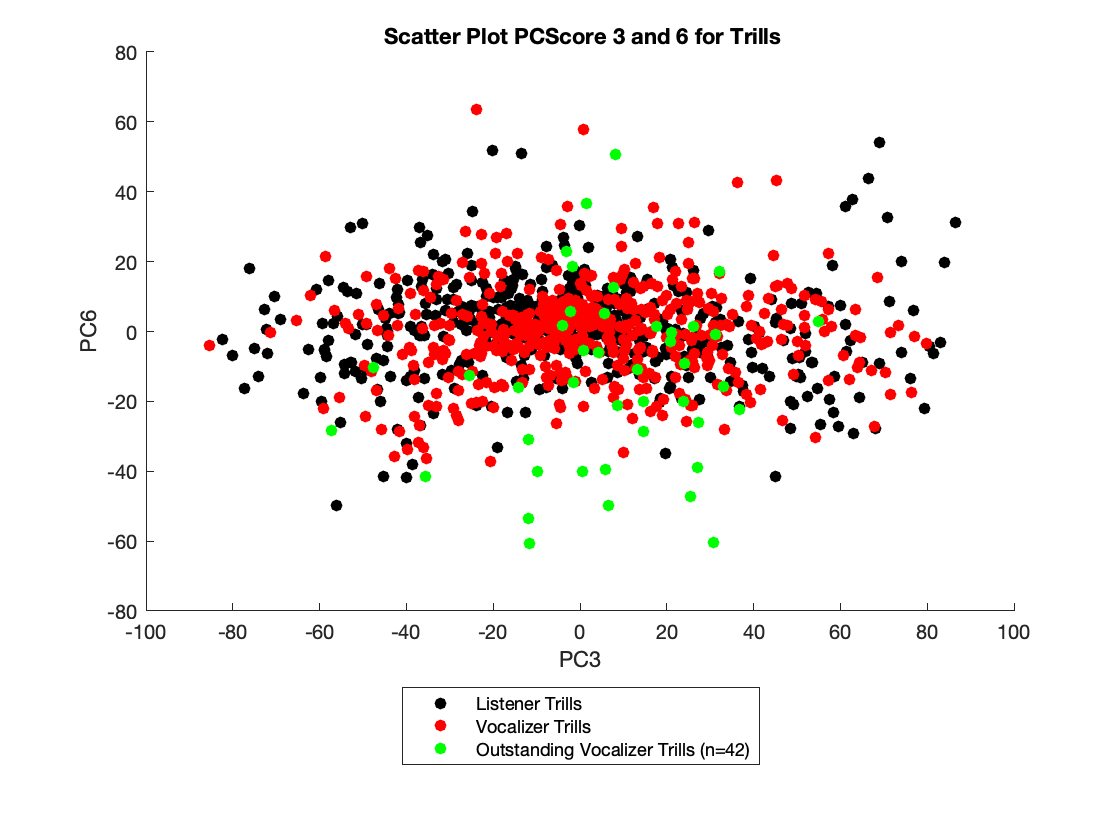


figure()
scatter(Score(OLT_cells,PCSigT(1)),Score(OLT_cells,PCSigT(2)),'ko', 'filled')
hold on


scatter(ScoreOVT(~OutstandingVoc(OVT_cells),1),ScoreOVT(~OutstandingVoc(OVT_cells),2), 'ro', 'filled')
hold on
scatter(ScoreOVT(logical(OutstandingVoc(OVT_cells)),1),ScoreOVT(logical(OutstandingVoc(OVT_cells)),2), 'go', 'filled')
hold on


legend({'Listener Trills', 'Vocalizer Trills', sprintf('Outstanding Vocalizer Trills (n=%d)',sum(logical(sum(OutstandingT,2))))}, 'Location', 'southoutside')
xlabel(sprintf('PC%d',PCSigT(1)))
ylabel(sprintf('PC%d',PCSigT(2)))
title(sprintf('{\b Scatter Plot PCScore %d and %d for Trills}',PCSigT(1),PCSigT(2)))
hold off

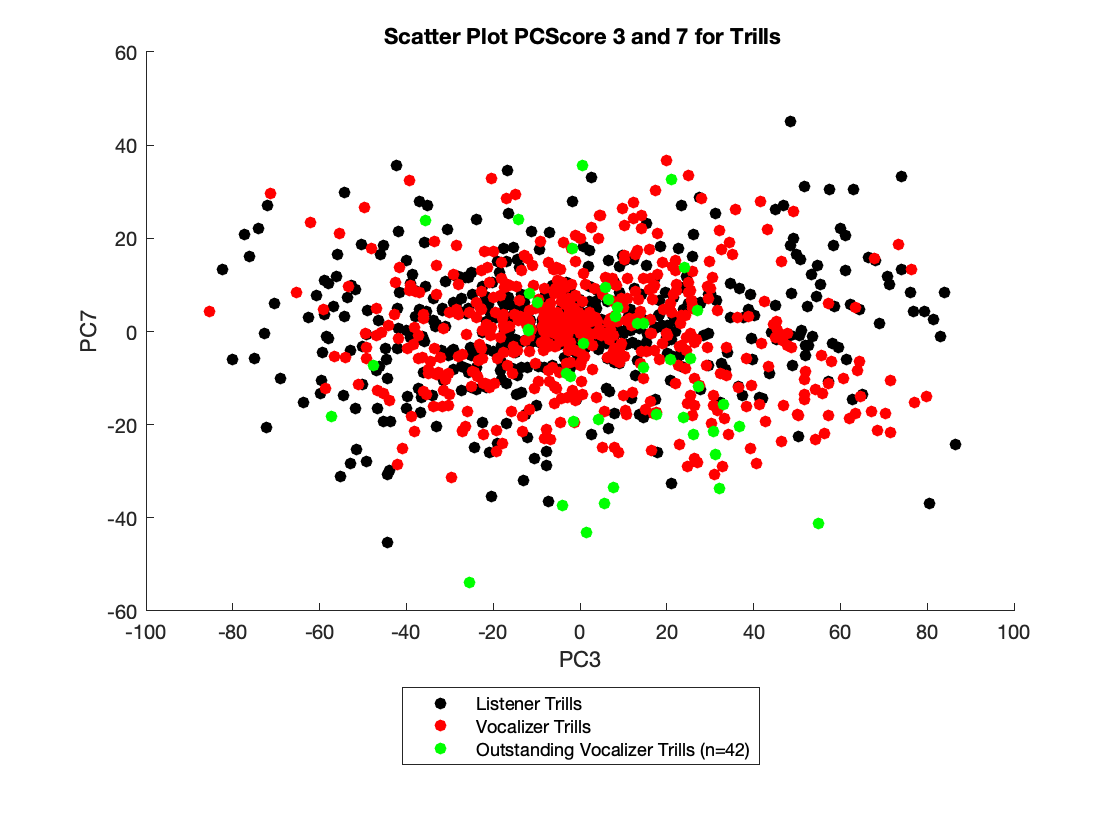

figure()
scatter(Score(OLT_cells,PCSigT(1)),Score(OLT_cells,PCSigT(3)),'ko', 'filled')
hold on


scatter(ScoreOVT(~OutstandingVoc(OVT_cells),1),ScoreOVT(~OutstandingVoc(OVT_cells),3), 'ro', 'filled')
hold on
scatter(ScoreOVT(logical(OutstandingVoc(OVT_cells)),1),ScoreOVT(logical(OutstandingVoc(OVT_cells)),3), 'go', 'filled')
hold on


legend({'Listener Trills', 'Vocalizer Trills', sprintf('Outstanding Vocalizer Trills (n=%d)',sum(OutstandingVoc(OVT_cells)))}, 'Location', 'southoutside')
xlabel(sprintf('PC%d',PCSigT(1)))
ylabel(sprintf('PC%d',PCSigT(3)))
title(sprintf('{\b Scatter Plot PCScore %d and %d for Trills}',PCSigT(1),PCSigT(3)))
hold off

% this is the list of cells in Score
ListCellsGAOpScore;

% These are cells with the out of the chart values for components that
% discriminate Listener from vocalizer
ListCellsGAOpScore(OutstandingVoc==1)

ans = 42×1 cell array
    {'/Volumes/JulieE8T/LMCResults/59834_20190617_SSM_1-78.mat' }
    {'/Volumes/JulieE8T/LMCResults/59834_20190618_SSS_1-77.mat' }
    {'/Volumes/JulieE8T/LMCResults/59834_20190618_SSM_1-73.mat' }
    {'/Volumes/JulieE8T/LMCResults/59834_20190621_SSM_1-92.mat' }
    {'/Volumes/JulieE8T/LMCResults/59834_20190622_SSM_3-162.mat'}
    {'/Volumes/JulieE8T/LMCResults/59834_20190623_SSS_2-116.mat'}
    {'/Volumes/JulieE8T/LMCResults/59834_20190623_SSM_1-108.mat'}
    {'/Volumes/JulieE8T/LMCResults/59834_20190623_SSM_1-94.mat' }
    {'/Volumes/JulieE8T/LMCResults/59834_20190623_SSM_3-188.mat'}
    {'/Volumes/JulieE8T/LMCResults/59834_20190624_SSS_1-104.mat'}
    {'/Volumes/JulieE8T/LMCResults/59834_20190624_SSM_3-209.mat'}
    {'/Volumes/JulieE8T/LMCResults/59834_20190624_SSM_3-219.mat'}
    {'/Volumes/JulieE8T/LMCResults/59834_20190625_SSM_1-123.mat'}
    {'/Volumes/JulieE8T/LMCResults/59834_20190625_SSM_2-169.mat'}
    {'/Volumes/JulieE8T/LMCResults/59834_20190625_SSM_

fprintf(1, 'There are %d/%d cells from vocalizer bats with out of the chart values for components that dicriminate Listeners from vocalizers', sum(OutstandingVoc==1), sum(~isnan(OutstandingVoc)))

There are 42/564 cells from vocalizer bats with out of the chart values for components that dicriminate Listeners from vocalizers

ListCellsVocPCAComponent = ListCellsGV(logical(VCells(:,1)));
save(fullfile(Path2AllData,'population_PCA_GLM_data.mat'), 'ListCellsVocPCAComponent','VCells', '-append')

% For the vocalizer cells with motor components, get values of Information on motor and auditory coherence in Free
% session and motor coherence in operant, along with the time resolution of
% these cells. I need to find what would be the optimal size of the
% Gaussian for the next step (PCA on time varying spike rate of each vocalization for
% each cell)
% Values of MI COherence with Vocal production in Operant
HDPath = '/Volumes/JulieE8T/LMCResults/';
MC = load(fullfile(HDPath,sprintf('MotorCoherence_%s_%s.mat', 'amp', 'Operant')));
% Gather data on Info
InfoMotorOpGVCells = nan(sum(VCells(:,1)),3);% first column value of info, 2nd pRandSpikePer, 3rd pRandVoc
DelayResolutionMotorOpGVCells = nan(sum(VCells(:,1)),3); % first column delay in ms, 2nd column resolution
NanCount = [];
for cc=1:length(MC.CellsPath)
    Ind=find(contains(ListCellsVocPCAComponent, MC.CellsPath(cc).name));
    if ~isempty(Ind)
        InfoMotorOpGVCells(Ind,1) = MC.Info(cc);
        if isnan(MC.Info(cc))
            NanCount = [NanCount Ind];
        end
        InfoMotorOpGVCells(Ind,2) = MC.Info_pRandSpikePerm(cc);
        InfoMotorOpGVCells(Ind,3) = MC.Info_pRandVoc(cc);
        DelayResolutionMotorOpGVCells(Ind,1) = MC.CoherencyT_DelayAtzero(cc);
        DelayResolutionMotorOpGVCells(Ind,2) = 1000./(2*MC.CoherenceWeightedFreq(cc));
    end
end
fprintf(1,'Could not find any value of Motor information in Operant for %d cells', length(NanCount))

Could not find any value of Motor information in Operant for 0 cells

NanCount


NanCount =

     []



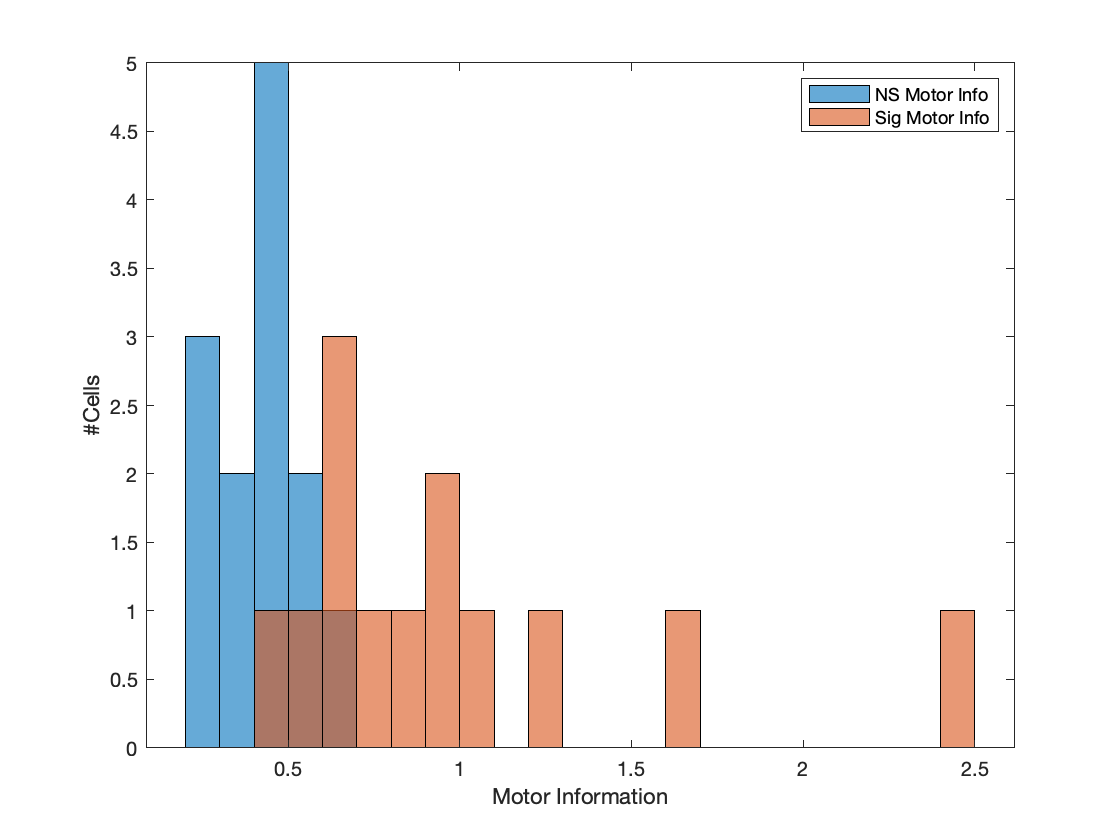

% Plot the values of coherence Information
ColPC = get(groot, 'DefaultAxesColorOrder');
SigMotorCells = (InfoMotorOpGVCells(:,2)<0.01);
SigGestureCells = (InfoMotorOpGVCells(:,3)<0.01);
figure()
histogram(InfoMotorOpGVCells(~SigMotorCells,1), 'BinWidth',0.1)
hold on
histogram(InfoMotorOpGVCells(SigMotorCells,1), 'BinWidth',0.1)
legend('NS Motor Info', 'Sig Motor Info')
ylabel('#Cells')
xlabel('Motor Information')
hold off

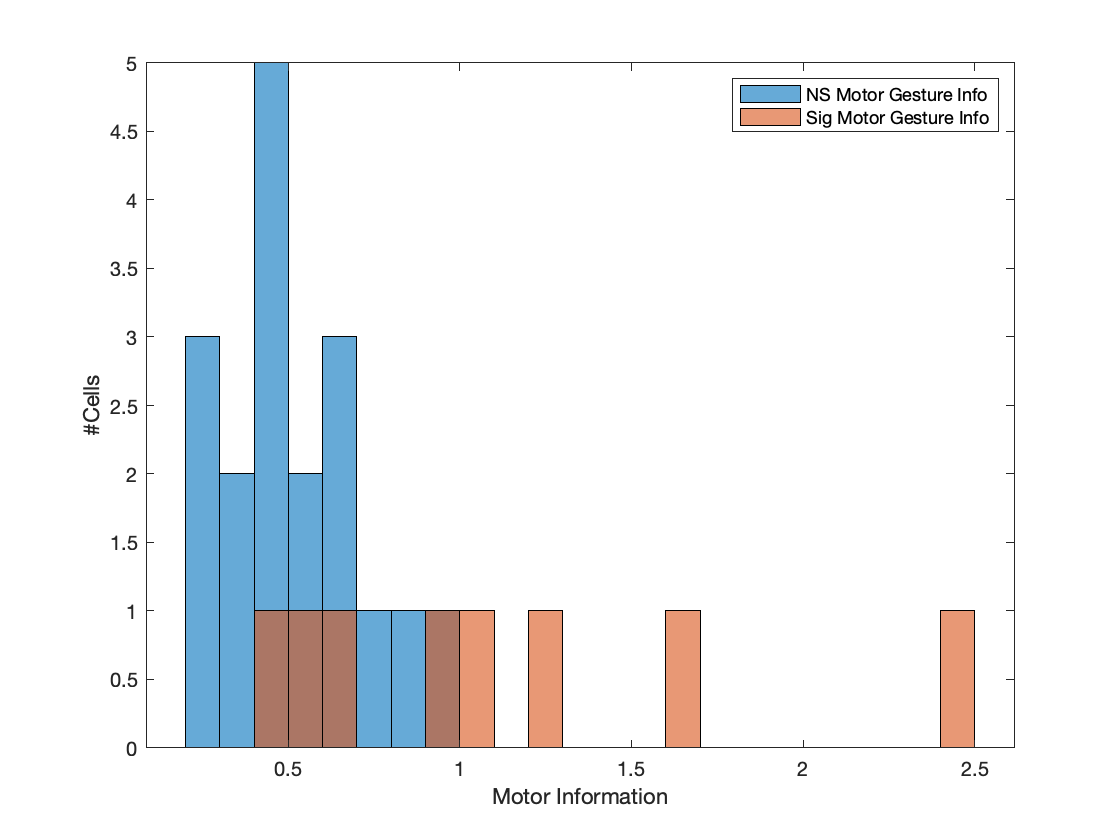


figure()
histogram(InfoMotorOpGVCells(~SigGestureCells,1), 'BinWidth',0.1)
hold on
histogram(InfoMotorOpGVCells(SigGestureCells,1), 'BinWidth',0.1)
legend('NS Motor Gesture Info', 'Sig Motor Gesture Info')
ylabel('#Cells')
xlabel('Motor Information')
hold off

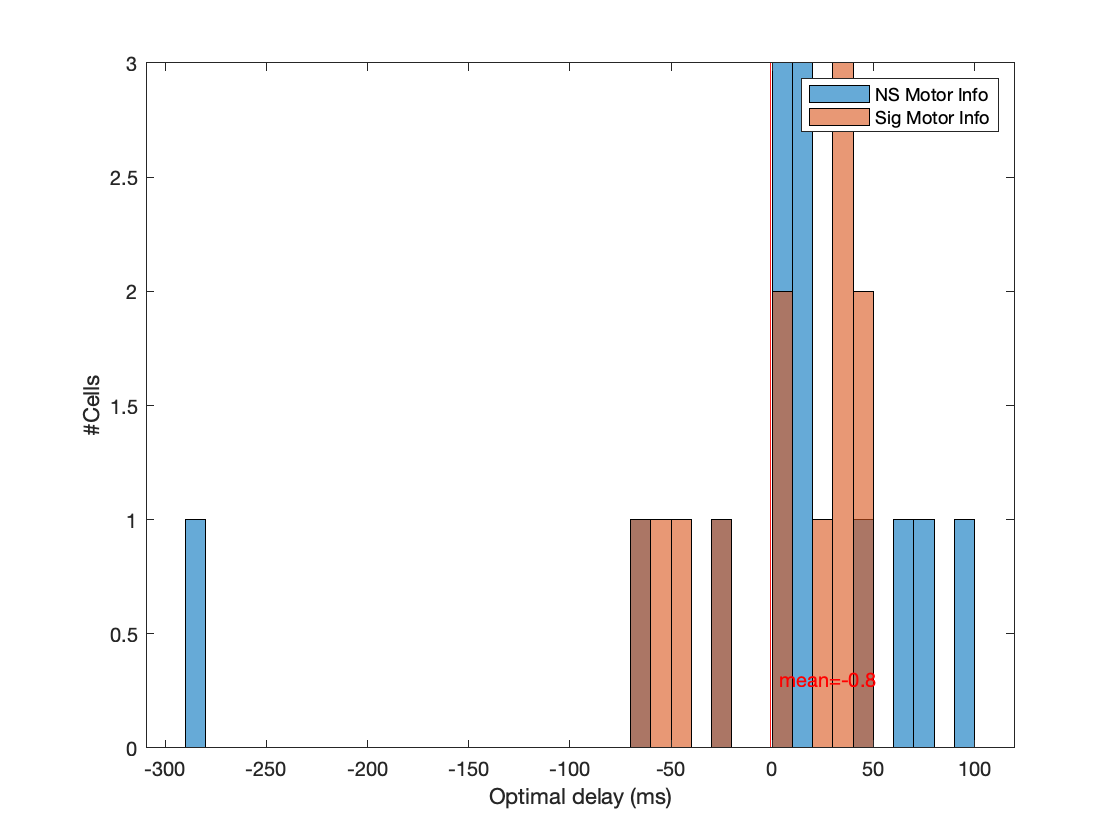

% Plot the values of coherence delay
ColPC = get(groot, 'DefaultAxesColorOrder');
SigMotorCells = (InfoMotorOpGVCells(:,2)<0.01);
SigGestureCells = (InfoMotorOpGVCells(:,3)<0.01);
figure()
histogram(DelayResolutionMotorOpGVCells(~SigMotorCells,1), 'BinWidth',10)
hold on
histogram(DelayResolutionMotorOpGVCells(SigMotorCells,1), 'BinWidth',10)
legend('NS Motor Info', 'Sig Motor Info')
legend('AutoUpdate', 'Off') 
vline(mean(DelayResolutionMotorOpGVCells(:,1), 'omitnan'), 'r-',sprintf('mean=%.1f',mean(DelayResolutionMotorOpGVCells(:,1),'omitnan') ))
ylabel('#Cells')
xlabel('Optimal delay (ms)')
hold off

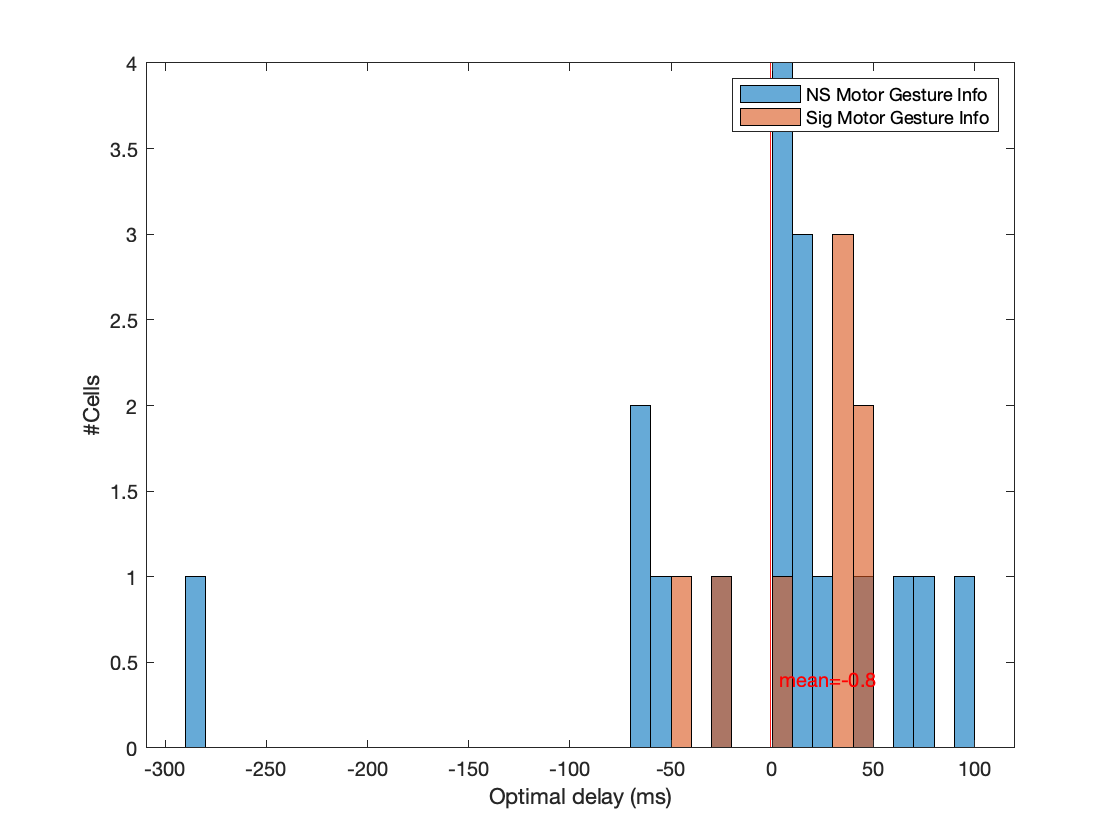


figure()
histogram(DelayResolutionMotorOpGVCells(~SigGestureCells,1), 'BinWidth',10)
hold on
histogram(DelayResolutionMotorOpGVCells(SigGestureCells,1), 'BinWidth',10)
legend('NS Motor Gesture Info', 'Sig Motor Gesture Info')
legend('AutoUpdate', 'Off')
vline(mean(DelayResolutionMotorOpGVCells(:,1),'omitnan'), 'r-',sprintf('mean=%.1f',mean(DelayResolutionMotorOpGVCells(:,1),'omitnan') ))
ylabel('#Cells')
xlabel('Optimal delay (ms)')
hold off

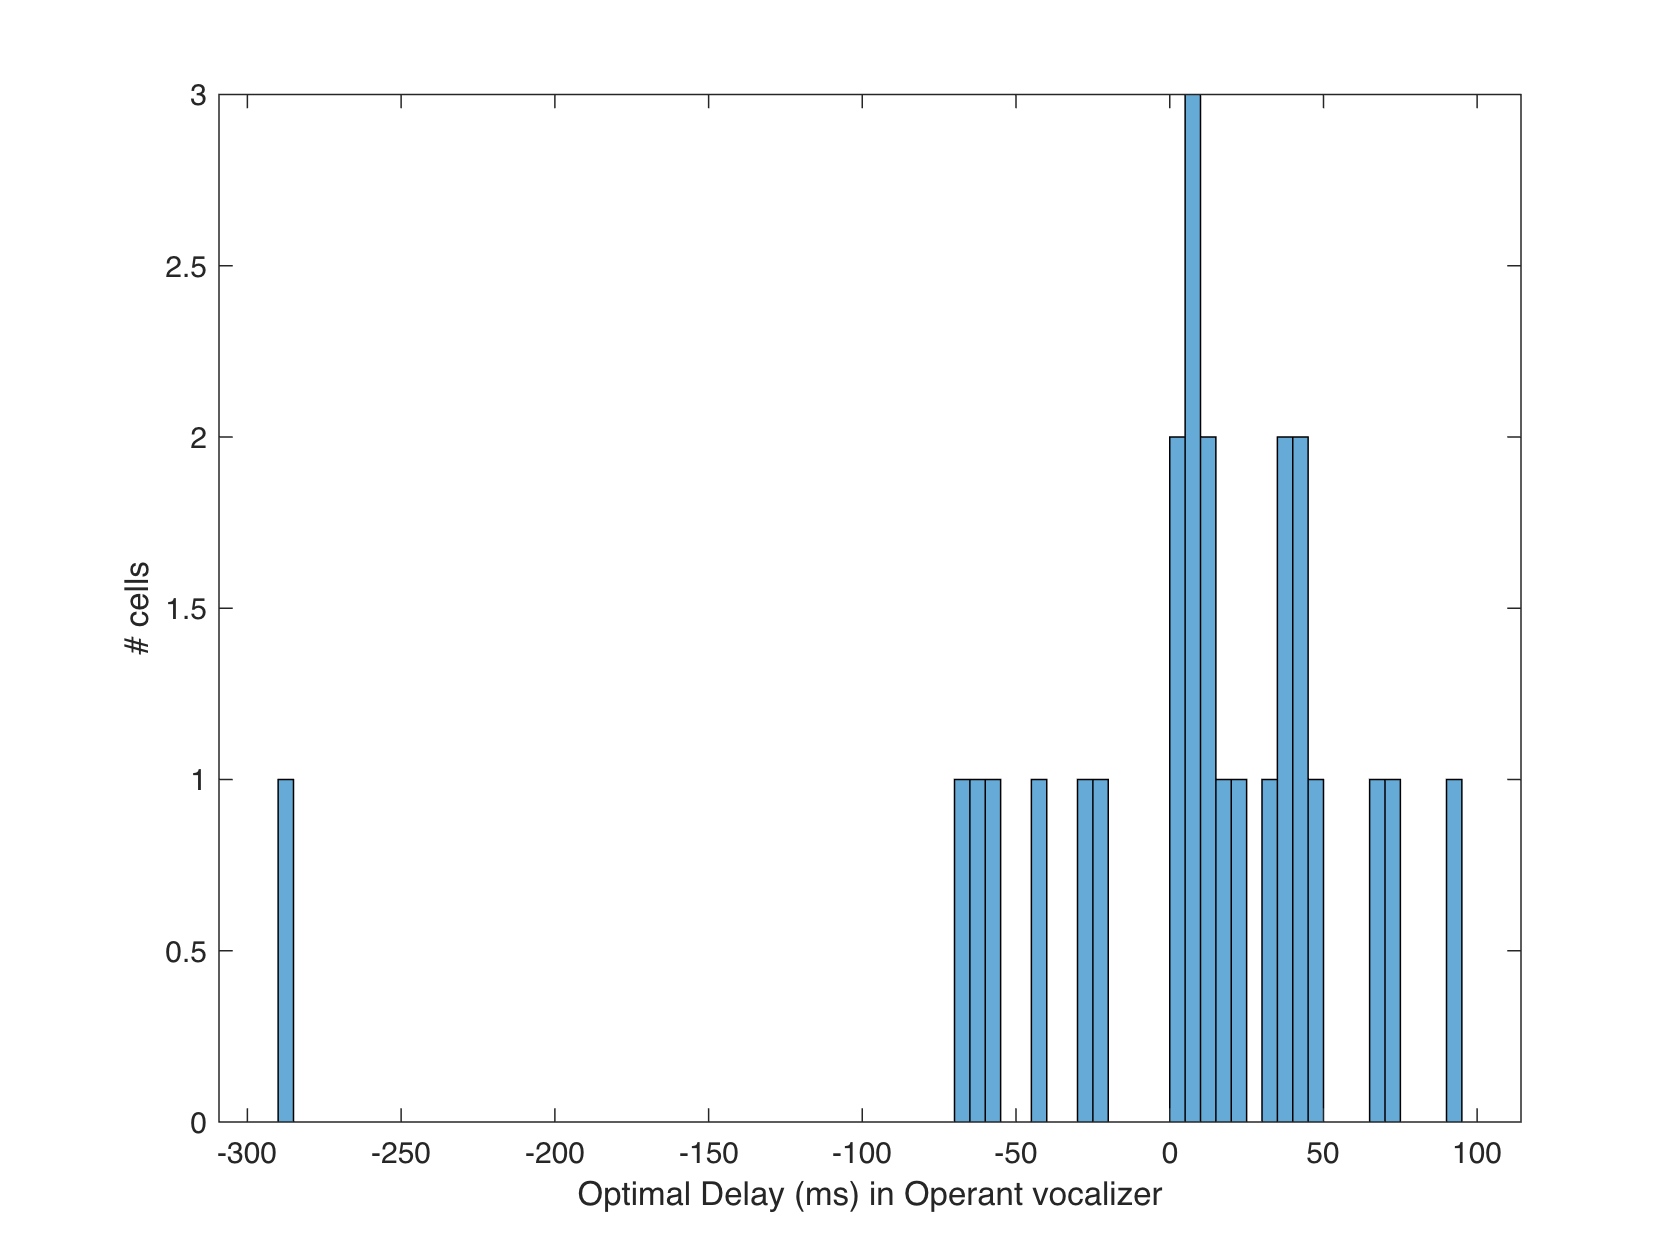

% plot the value of optimal Delay and Optimal resolution for these cells
% during Operant
histogram(DelayResolutionMotorOpGVCells(:,1), 'BinWidth',5)
hold on
vline(mean(DelayResolutionMotorOpGVCells(:,1)), 'r-',sprintf('mean=%.1f',mean(DelayResolutionMotorOpGVCells(:,1)) ))
hold off
ylabel('# cells')
xlabel('Optimal Delay (ms) in Operant vocalizer')

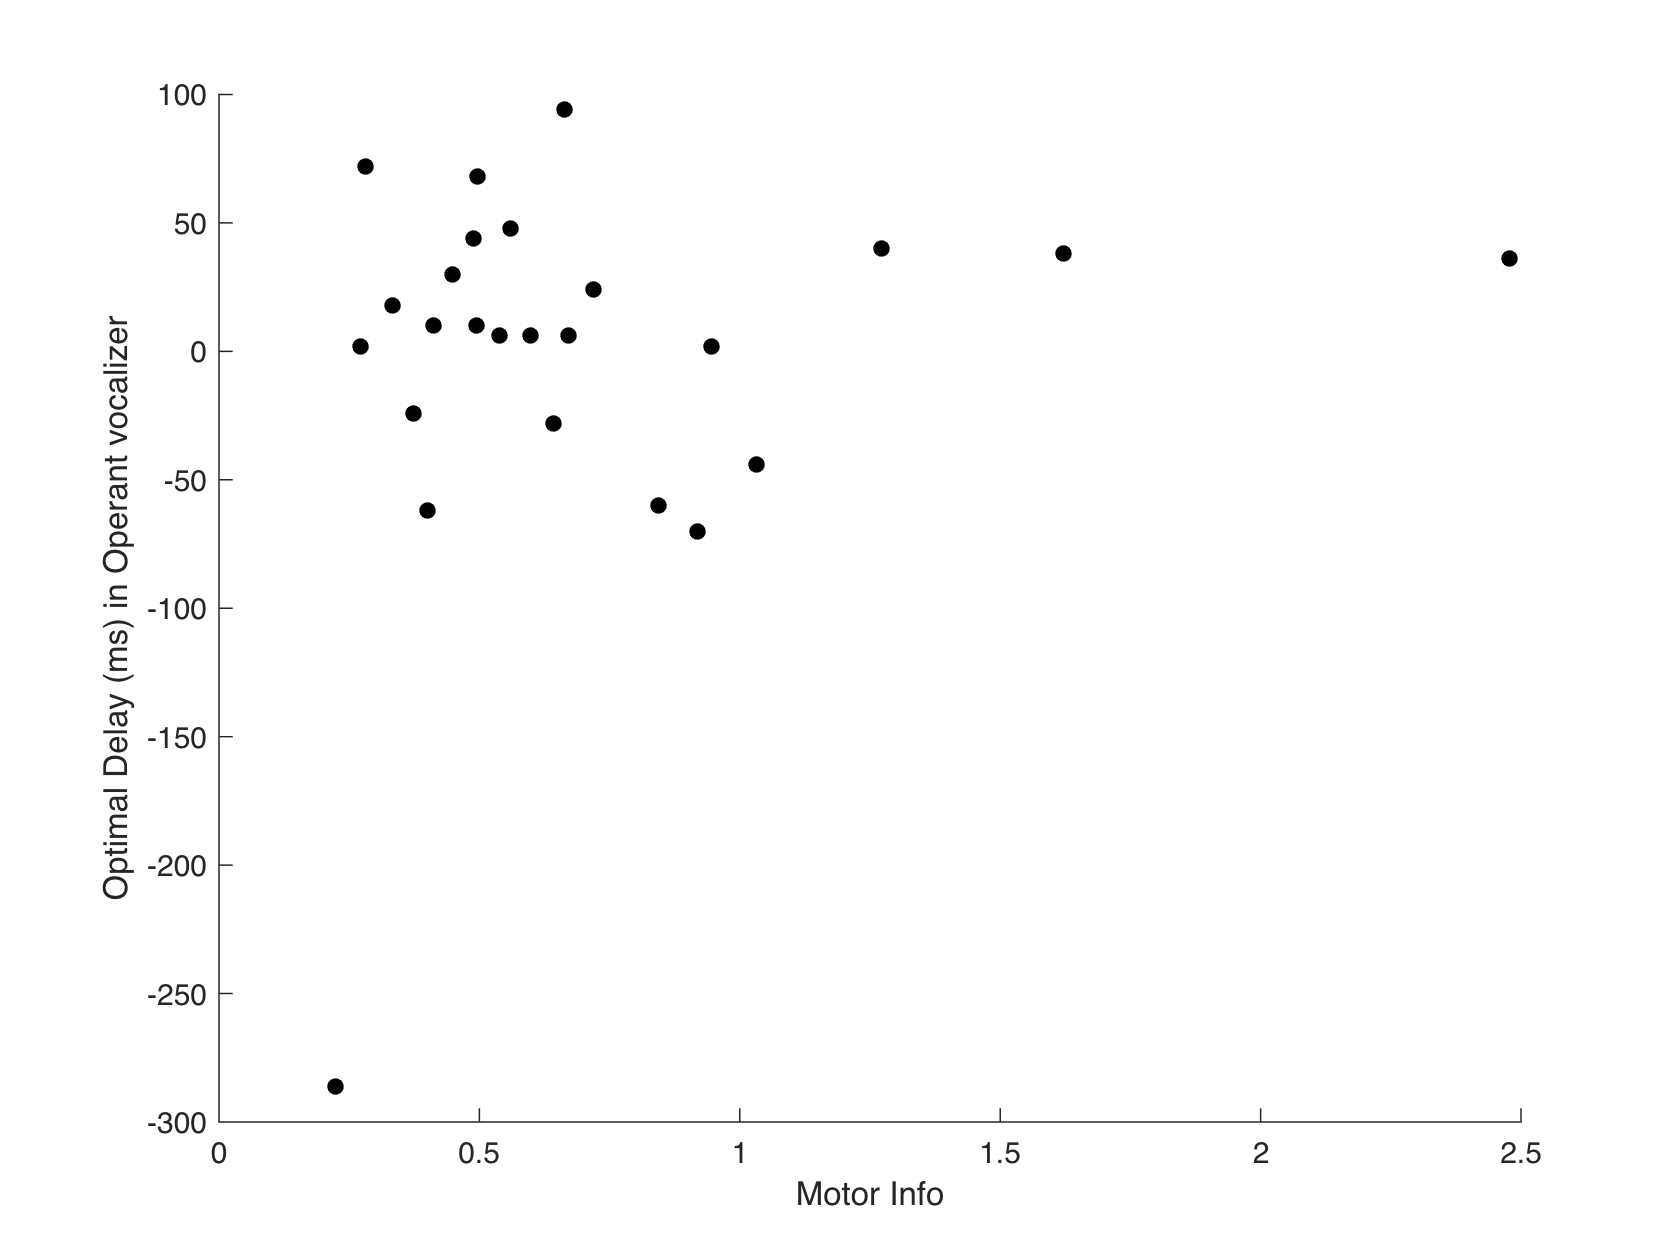

figure()
scatter(InfoMotorOpGVCells(:,1),DelayResolutionMotorOpGVCells(:,1), 30, 'k', 'filled')
xlabel('Motor Info')
ylabel('Optimal Delay (ms) in Operant vocalizer')

fprintf(1,'Minimum optimal delay = %d ms', min(DelayResolutionMotorOpGVCells(:,1)))

Minimum optimal delay = -286 ms

histogram(DelayResolutionMotorOpGVCells(:,2), 'BinWidth',1)
hold on
vline(mean(DelayResolutionMotorOpGVCells(:,2)), 'r-',sprintf('mean=%.1f',mean(DelayResolutionMotorOpGVCells(:,2)) ))
fprintf(1,'Mean optimal resolution = %.2f ms', mean(DelayResolutionMotorOpGVCells(:,2)))

Mean optimal resolution = 9.59 ms

hold on
vline(median(DelayResolutionMotorOpGVCells(:,2)), 'b-',sprintf('median=%.1f',median(DelayResolutionMotorOpGVCells(:,2)) ))
fprintf(1,'Median optimal resolution = %.2f ms', median(DelayResolutionMotorOpGVCells(:,2)))

Median optimal resolution = 7.81 ms

hold on
vline(quantile(DelayResolutionMotorOpGVCells(:,2), 0.25), 'g-',sprintf('Q25=%.1f',quantile(DelayResolutionMotorOpGVCells(:,2),0.25)))
fprintf(1,'75%% of cells have optimal resolution > %.2f ms', quantile(DelayResolutionMotorOpGVCells(:,2),0.25))

75% of cells have optimal resolution > 5.42 ms

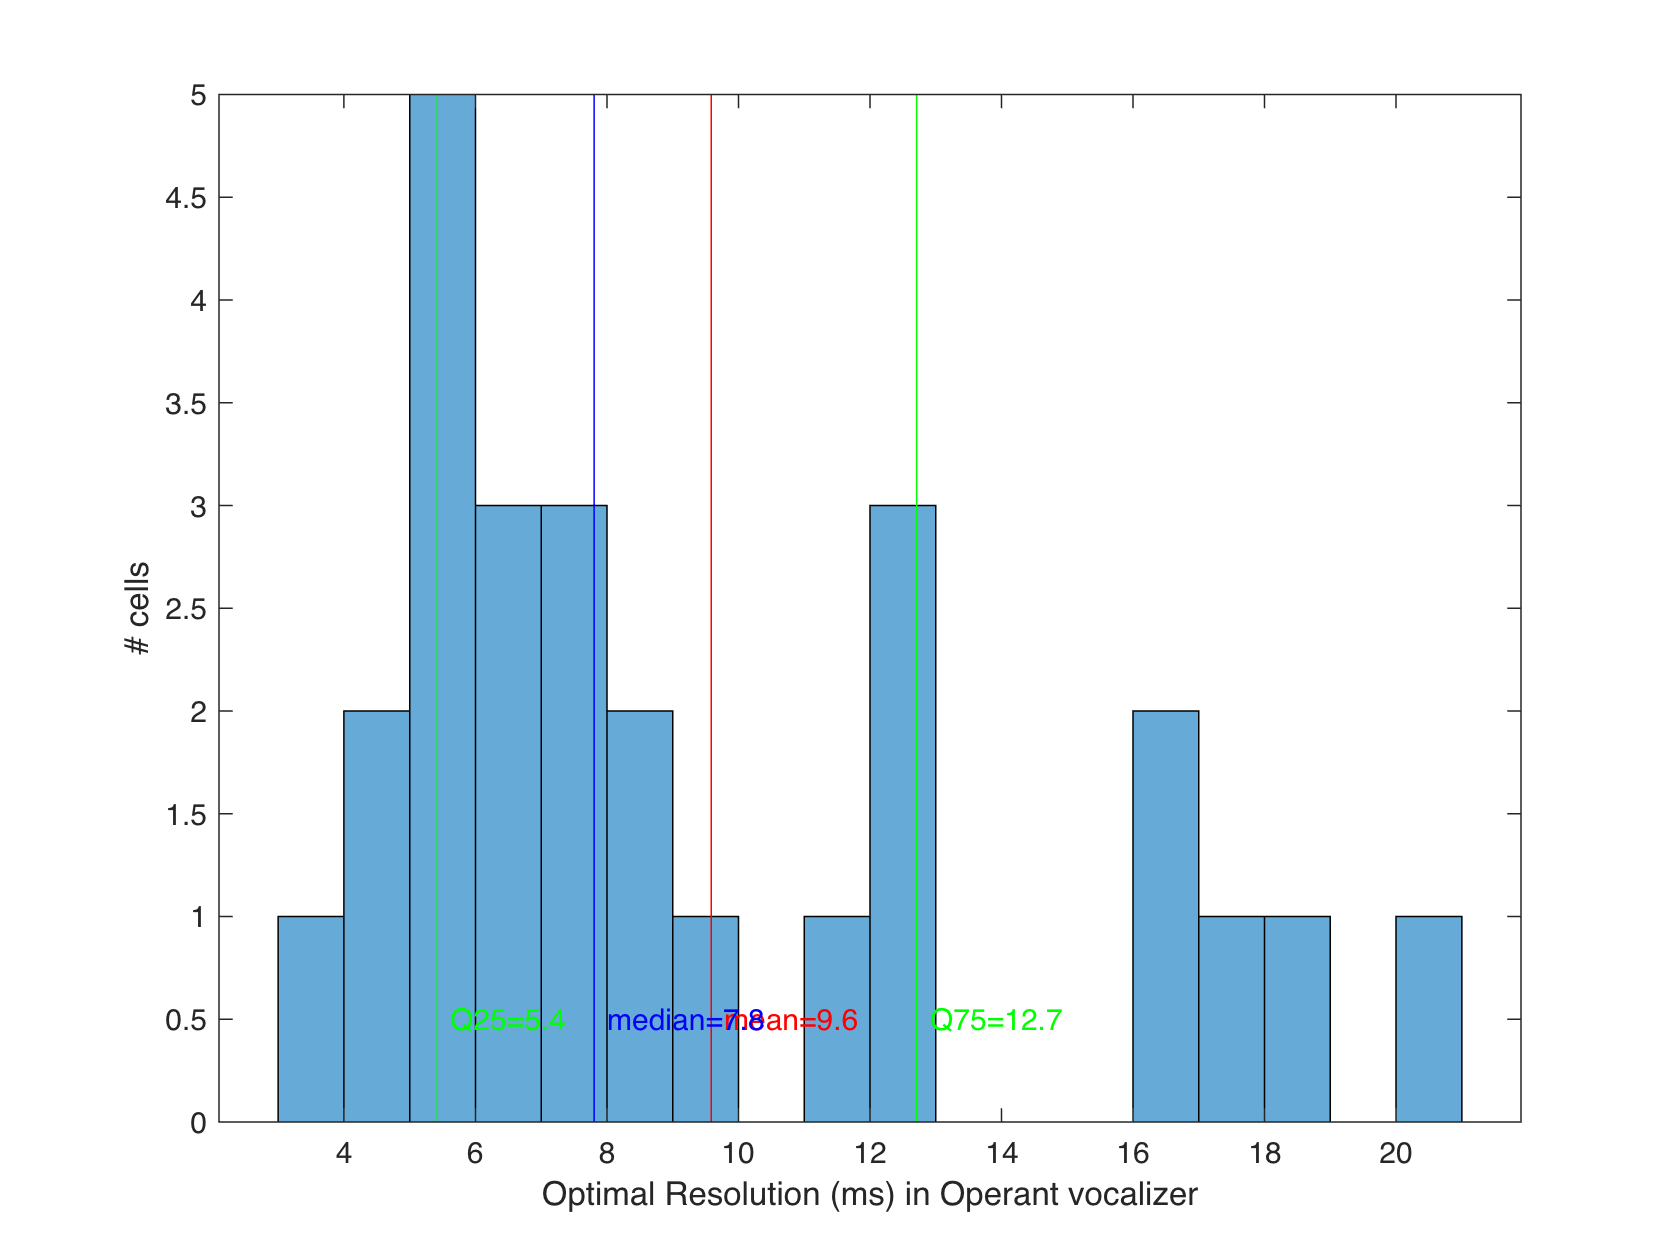

hold on
vline(quantile(DelayResolutionMotorOpGVCells(:,2), 0.75), 'g-',sprintf('Q75=%.1f',quantile(DelayResolutionMotorOpGVCells(:,2),0.75)))
ylabel('# cells')
xlabel('Optimal Resolution (ms) in Operant vocalizer')
hold off

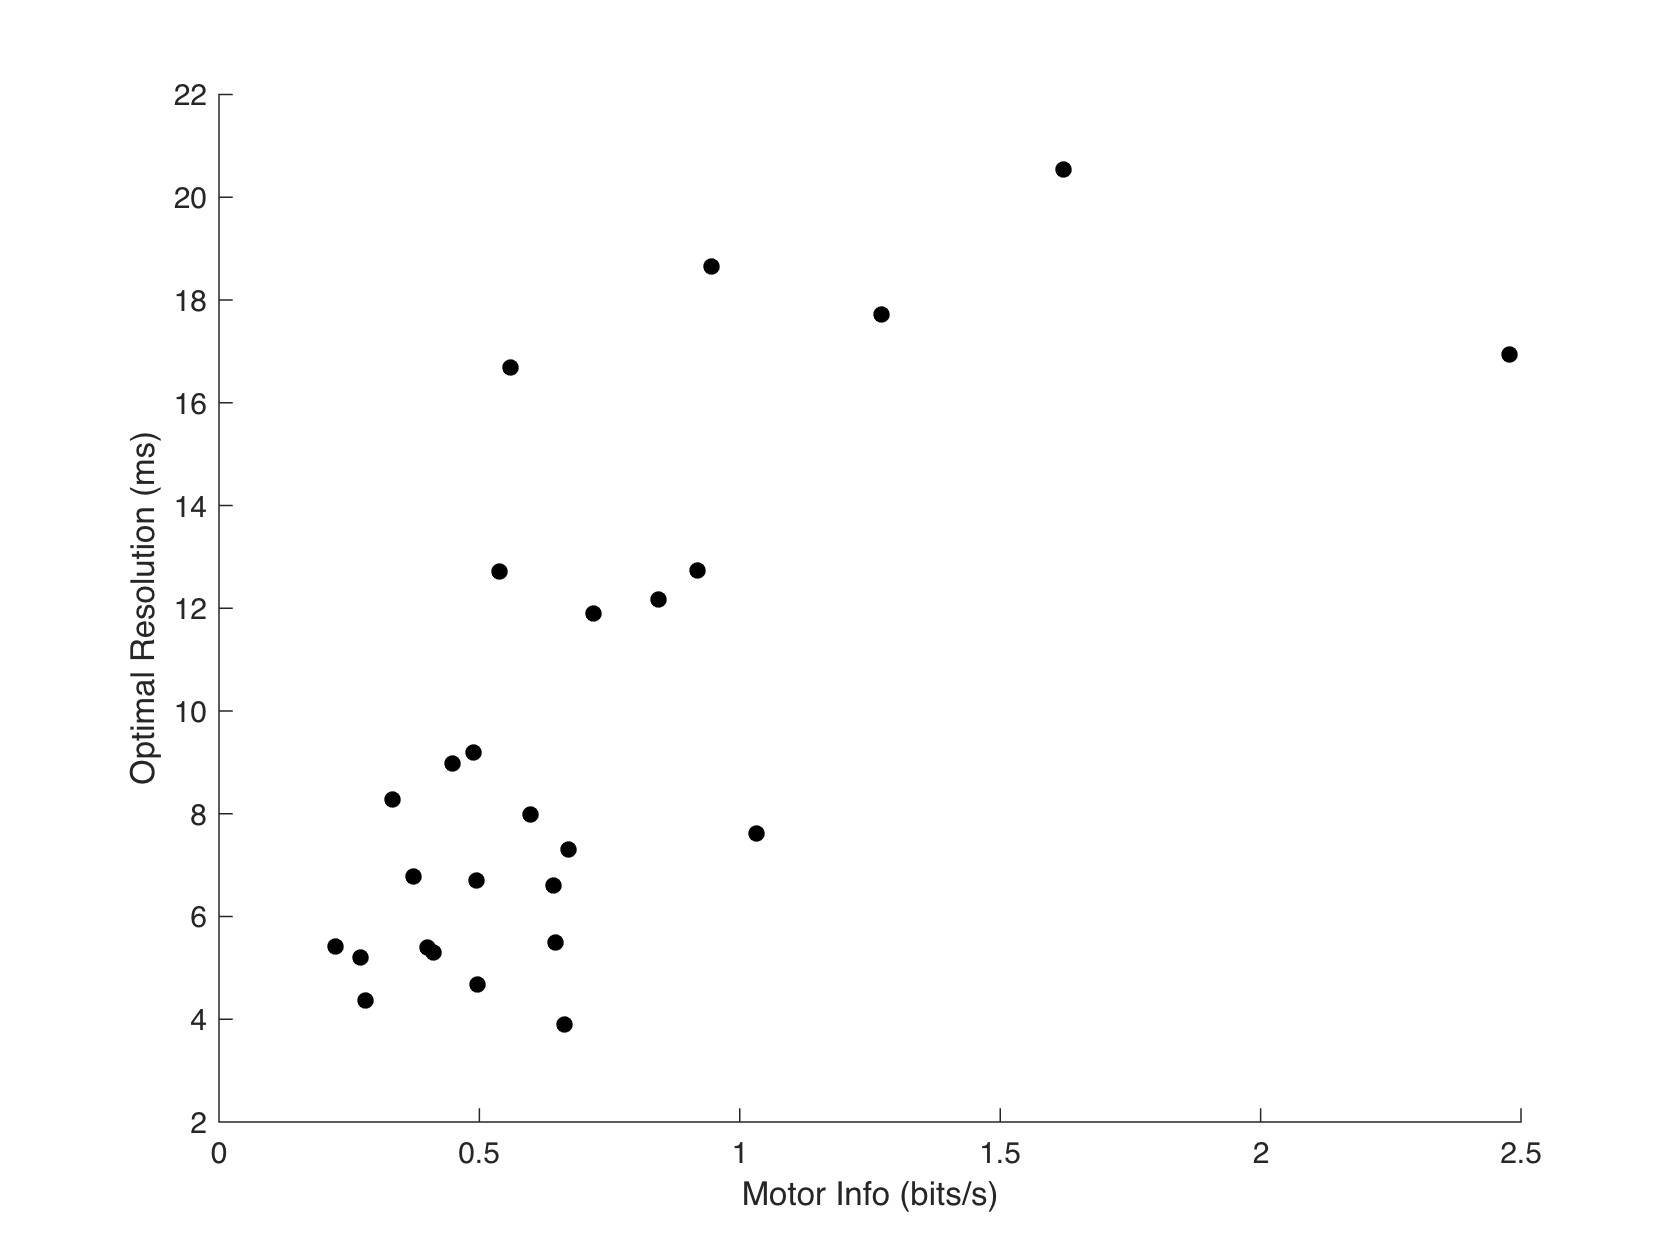

scatter(InfoMotorOpGVCells(:,1),DelayResolutionMotorOpGVCells(:,2), 30, 'k', 'filled')
xlabel('Motor Info (bits/s)')
ylabel('Optimal Resolution (ms)')